clear;
clc;
FS = 48000;
fc = 15000; %% modulating frequency

# **CA1-Q2-810101429**

## ***A:***

***Reading the input:***

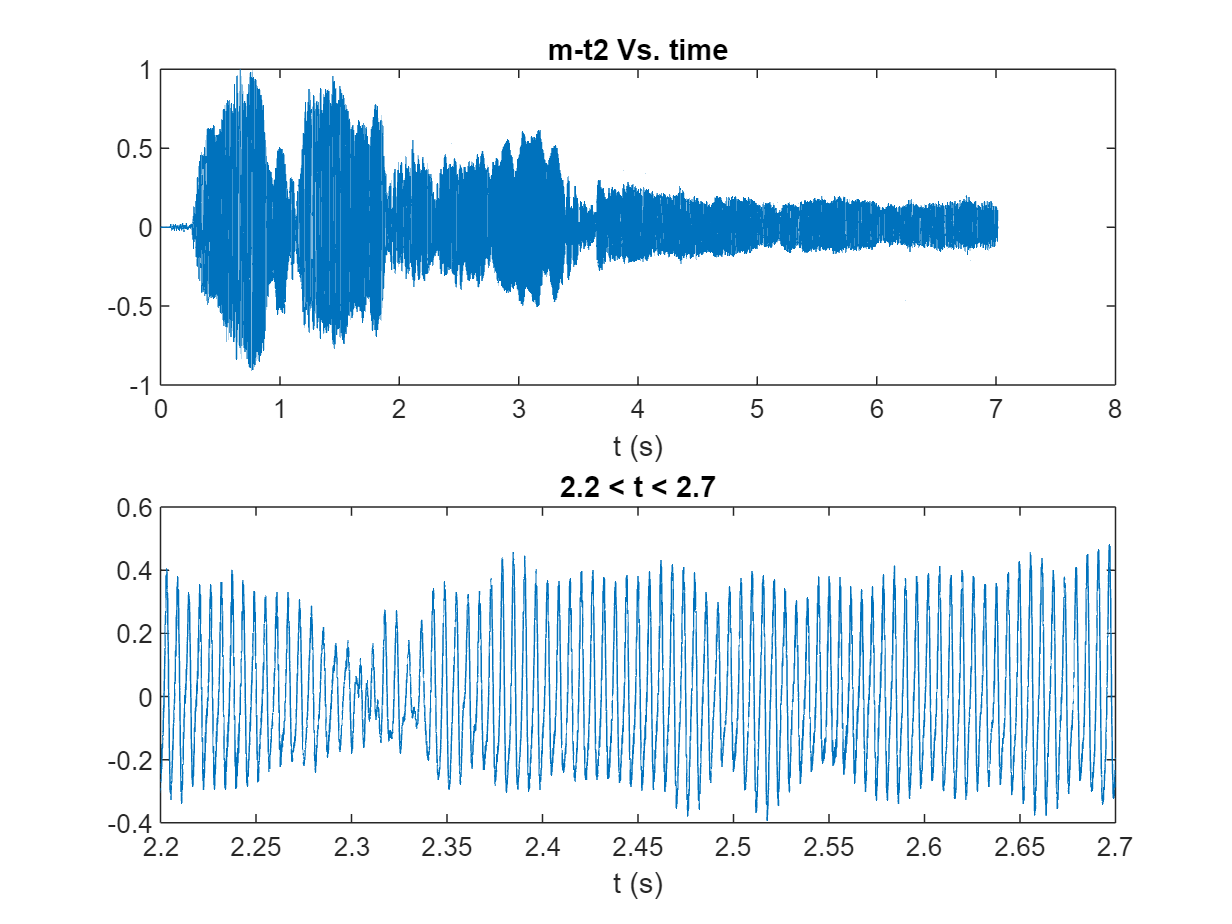

t2 = audioread('m_t2.mp3');
t2 = t2/max(abs(t2));

% sound(t2, FS);

time_domain = (0:length(t2)-1) / FS;
time_domain2 = time_domain';
figure;
subplot(2,1,1);
plot(time_domain, t2);
xlabel('t (s)');
title('m-t2 Vs. time');
subplot(2,1,2);
plot(time_domain, t2);
xlabel('t (s)');
title('2.2 < t < 2.7');
xlim([2.2, 2.7]);

***Calculating the Fourier Transform of the input signal:***

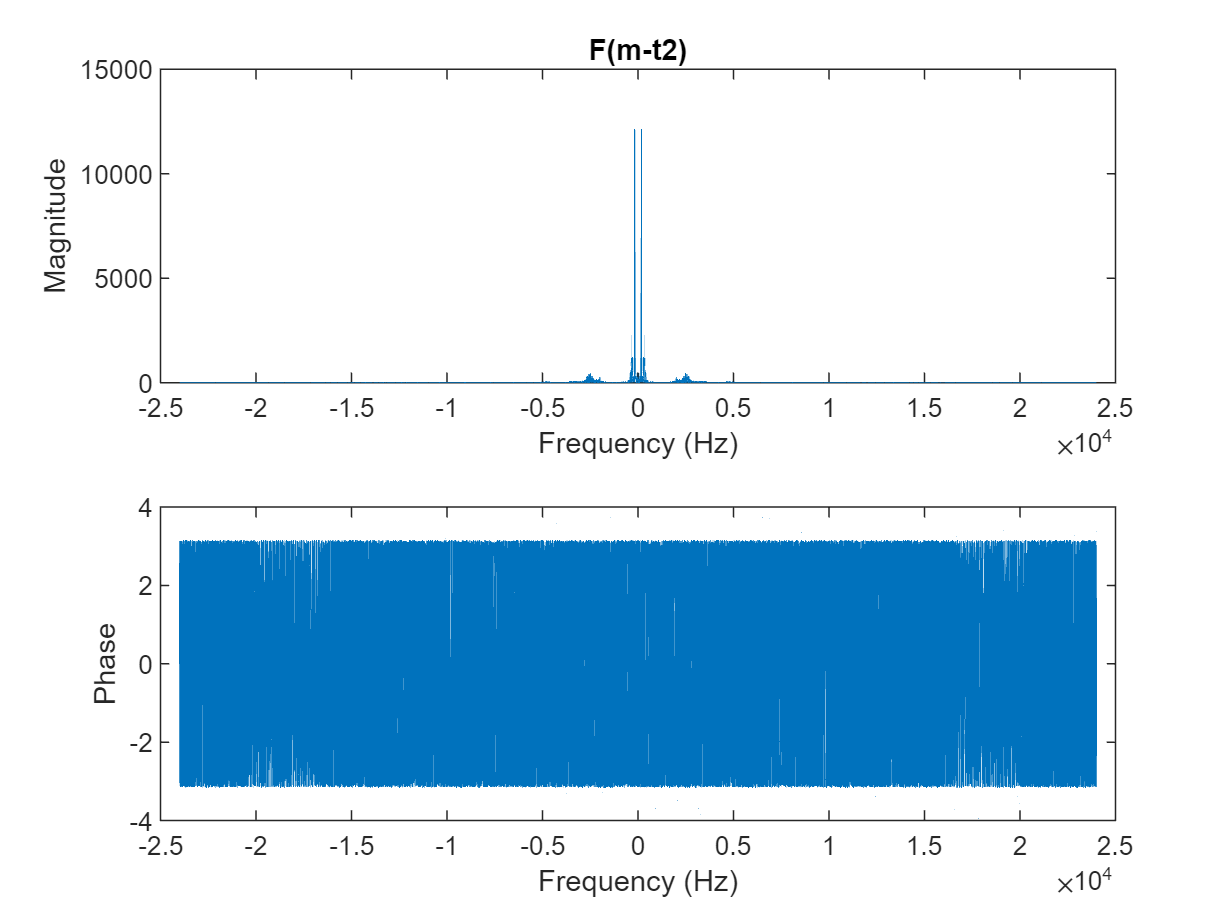



Ft2 = fftshift(fft(t2));
n_t2 = length(t2);
freq_domain = (-n_t2/2:n_t2/2-1)*(FS/n_t2);


figure;
subplot(2,1,1);
plot(freq_domain,abs(Ft2));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(m-t2)');
subplot(2,1,2);
plot(freq_domain,angle(Ft2));
xlabel('Frequency (Hz)');
ylabel('Phase');

## ***B:***

#### Filtering:

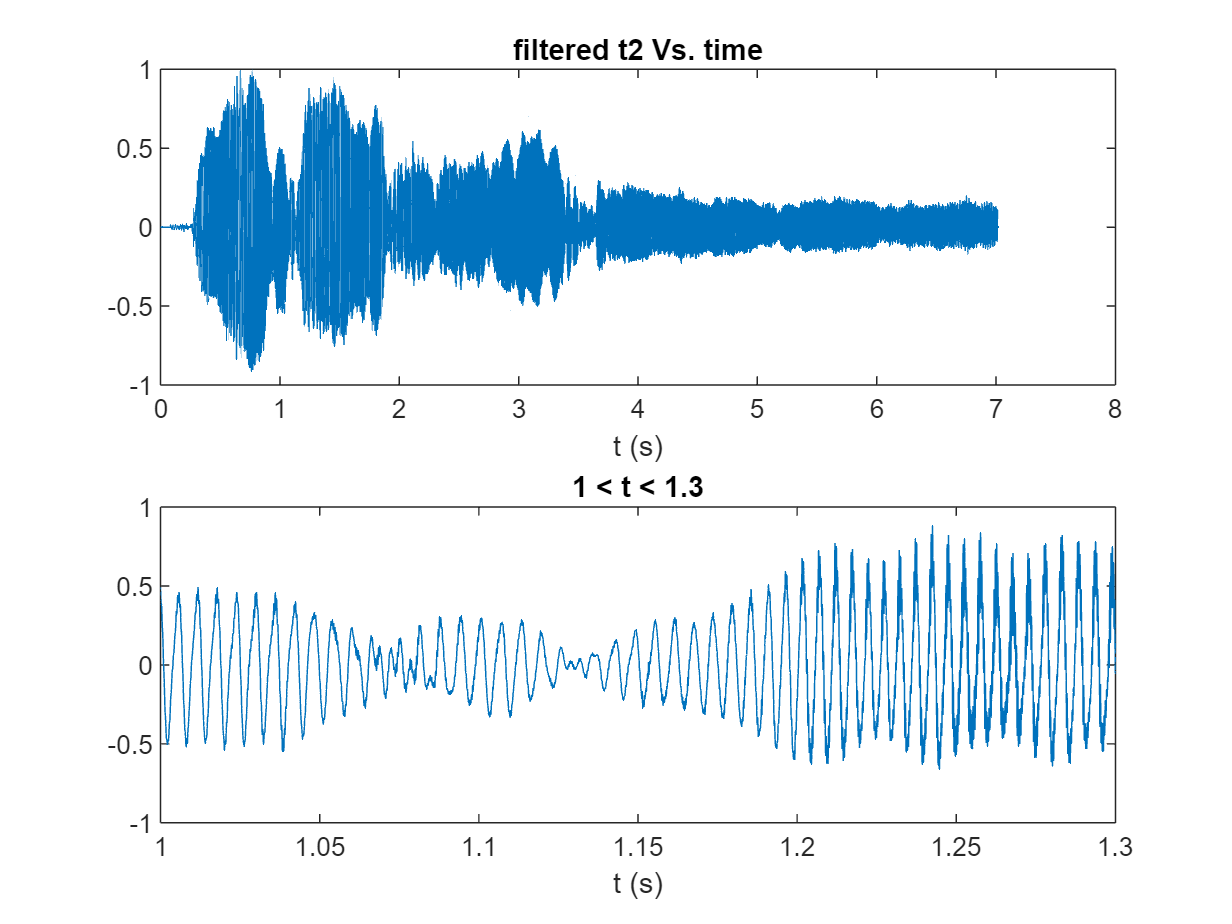


Ft2_filtered_5k = LPfilter(Ft2, freq_domain, 5000);
t2_filtered_5k = ifft(ifftshift(Ft2_filtered_5k));
% sound(t2_filtered_5k, FS);

%% ploting

figure;
subplot(2,1,1);
plot(time_domain, t2_filtered_5k);
xlabel('t (s)');
title('filtered t2 Vs. time');
subplot(2,1,2);
plot(time_domain, t2_filtered_5k);
xlabel('t (s)');
title('1 < t < 1.3');
xlim([1, 1.3]);

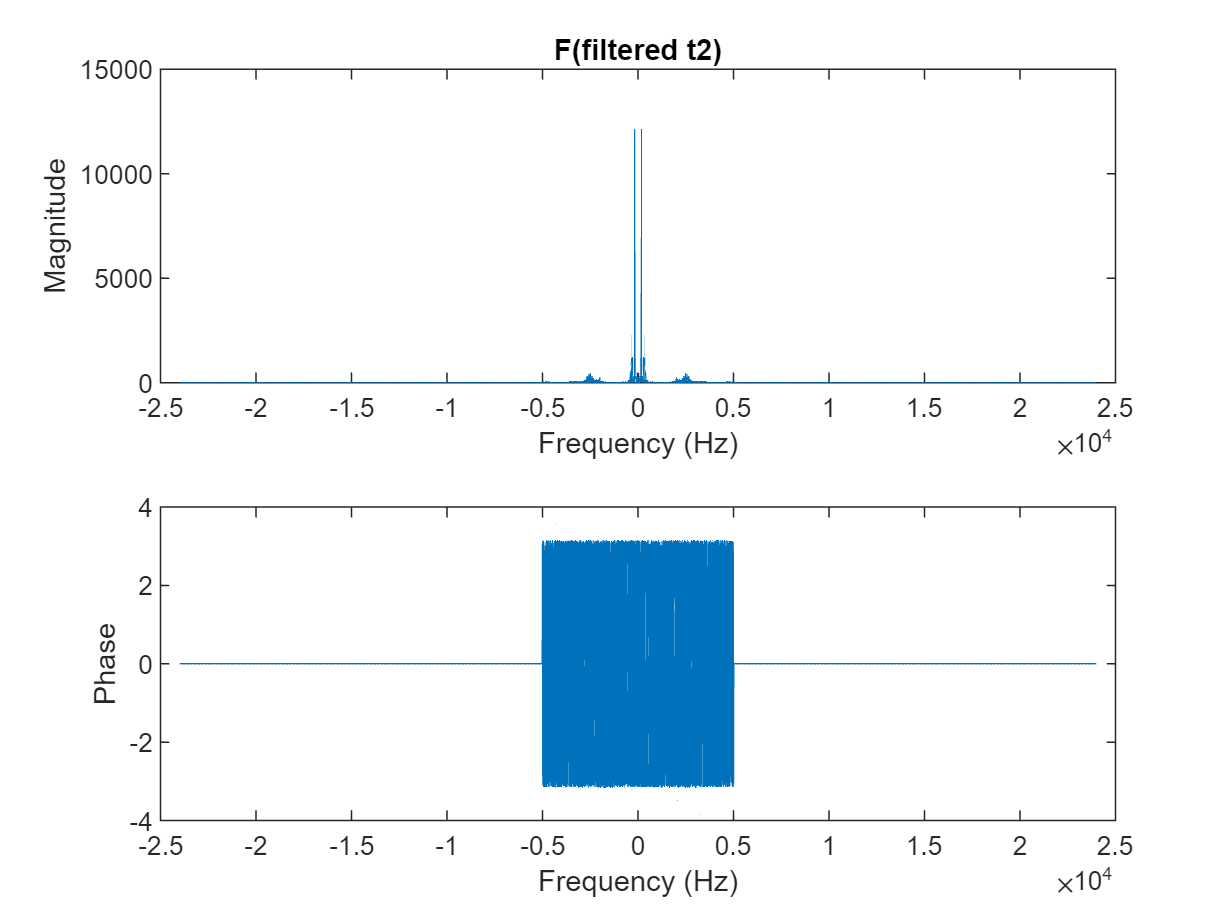


figure;
subplot(2,1,1);
plot(freq_domain,abs(Ft2_filtered_5k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(filtered t2)');
subplot(2,1,2);
plot(freq_domain,angle(Ft2_filtered_5k));
xlabel('Frequency (Hz)');
ylabel('Phase');

#### Modulating:

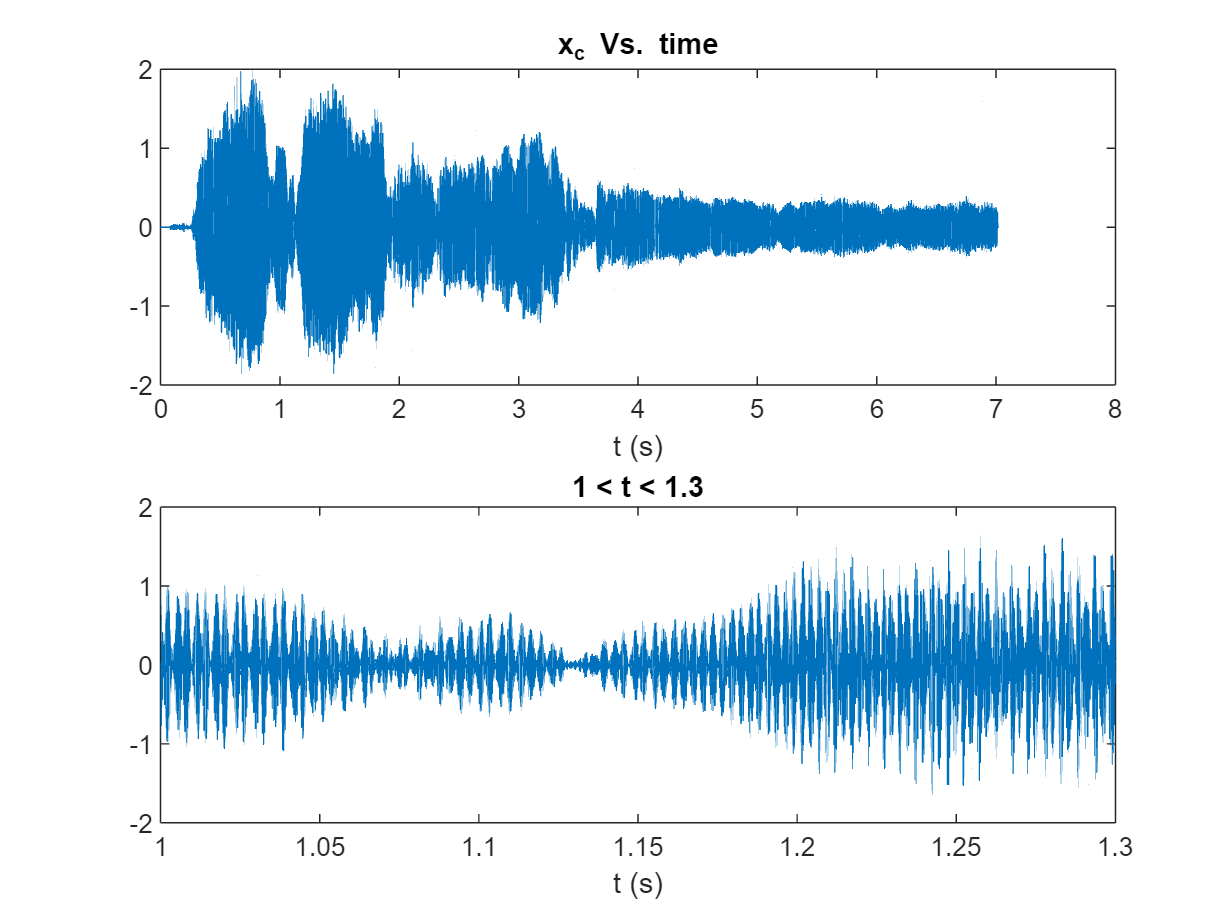

x_c = 2*cos(2*pi*fc*time_domain2) .* t2_filtered_5k;

figure;
subplot(2,1,1);
plot(time_domain, x_c);
xlabel('t (s)');
title('x_c Vs. time');
subplot(2,1,2);
plot(time_domain, x_c);
xlabel('t (s)');
title('1 < t < 1.3');
xlim([1, 1.3]);

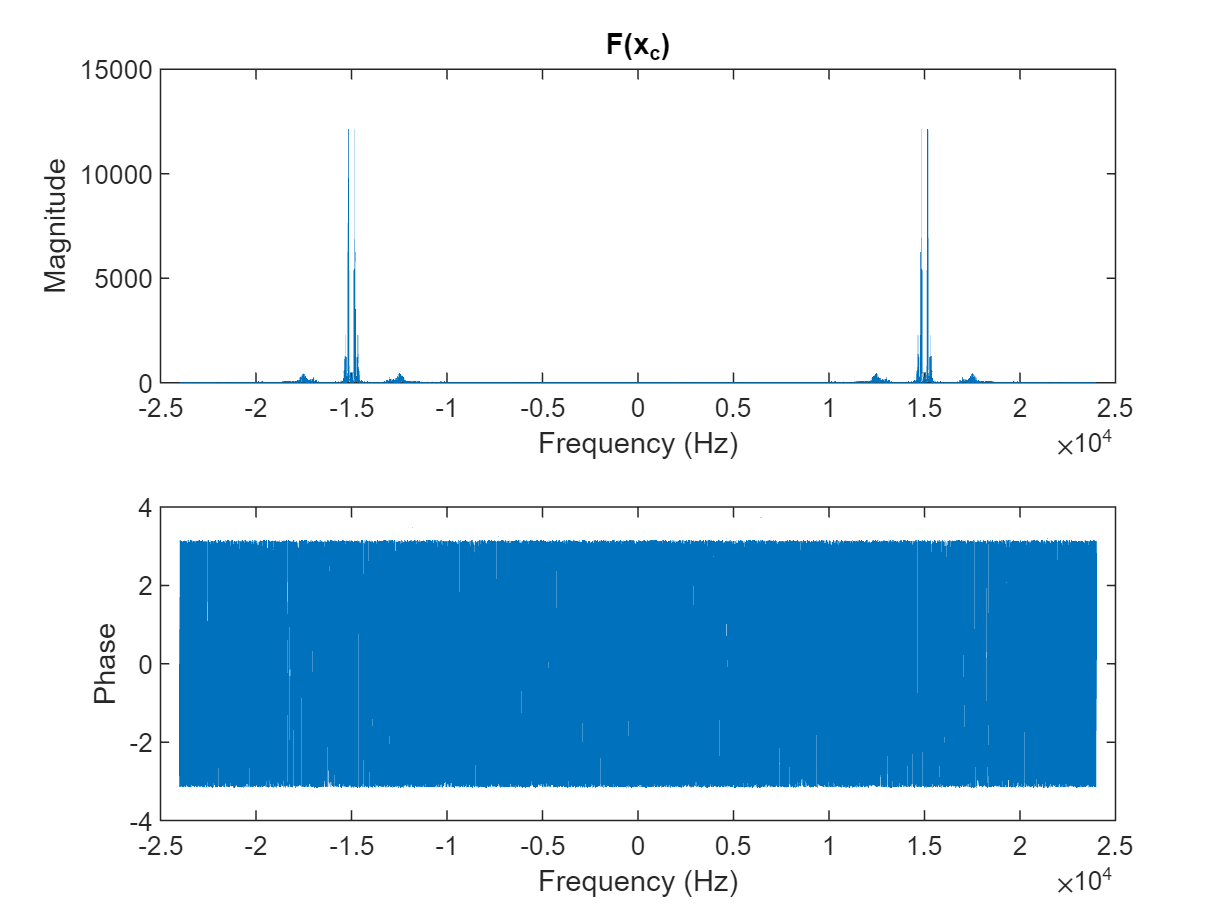

F_x_c = fftshift(fft(x_c));

figure;
subplot(2,1,1);
plot(freq_domain,abs(F_x_c));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(x_c)');
subplot(2,1,2);
plot(freq_domain,angle(F_x_c));
xlabel('Frequency (Hz)');
ylabel('Phase');

## ***C:***

#### Demodulating

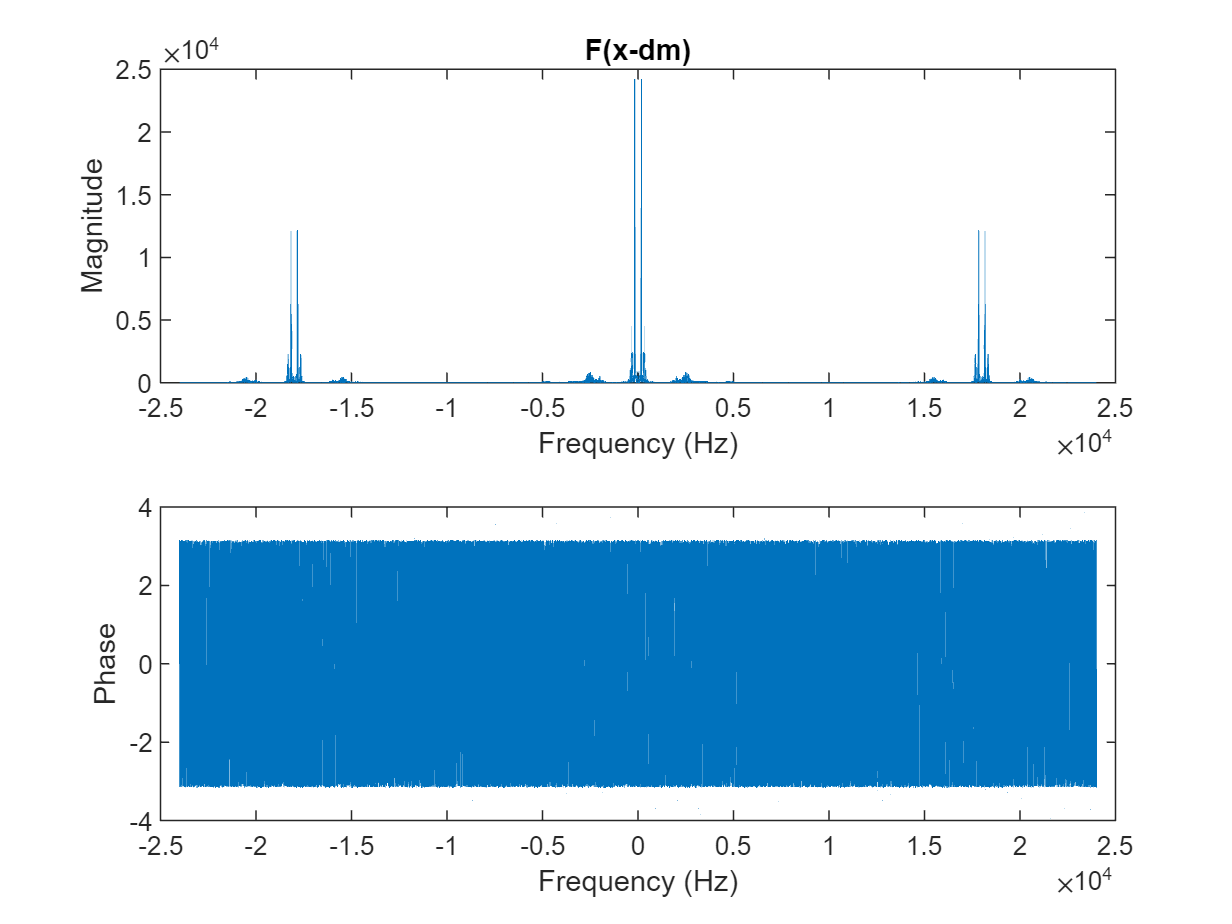


x_dm = 2*cos(2*pi*fc*time_domain2) .* x_c;
F_x_dm = fftshift(fft(x_dm));

F_X_final = LPfilter(F_x_dm, freq_domain, 5000);
x_final = ifft(ifftshift(F_X_final));

% sound(t2,FS);
% sound(x_final, FS);

figure;
subplot(2,1,1);
plot(freq_domain,abs(F_x_dm));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(x-dm)');
subplot(2,1,2);
plot(freq_domain,angle(F_x_dm));
xlabel('Frequency (Hz)');
ylabel('Phase');

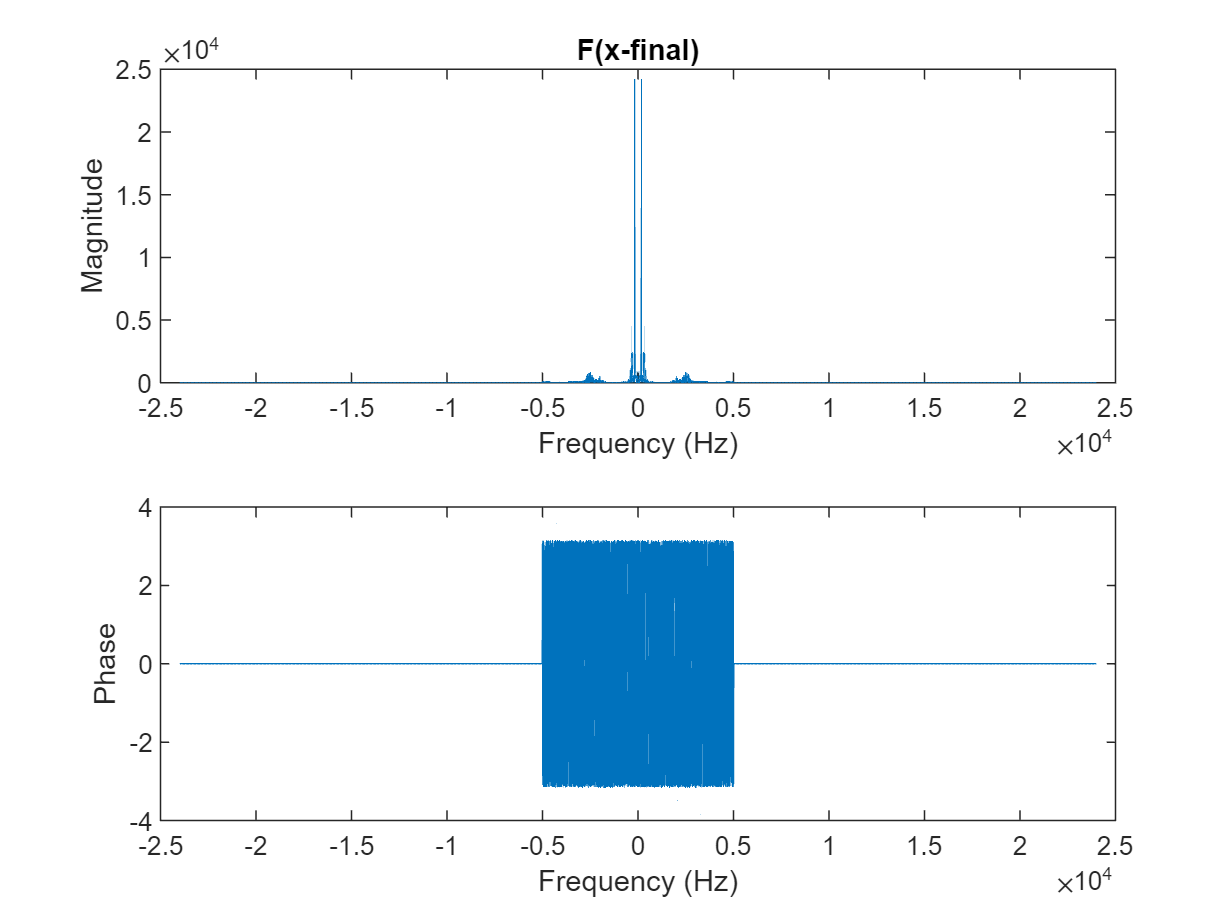



figure;
subplot(2,1,1);
plot(freq_domain,abs(F_X_final));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(x-final)');
subplot(2,1,2);
plot(freq_domain,angle(F_X_final));
xlabel('Frequency (Hz)');
ylabel('Phase');

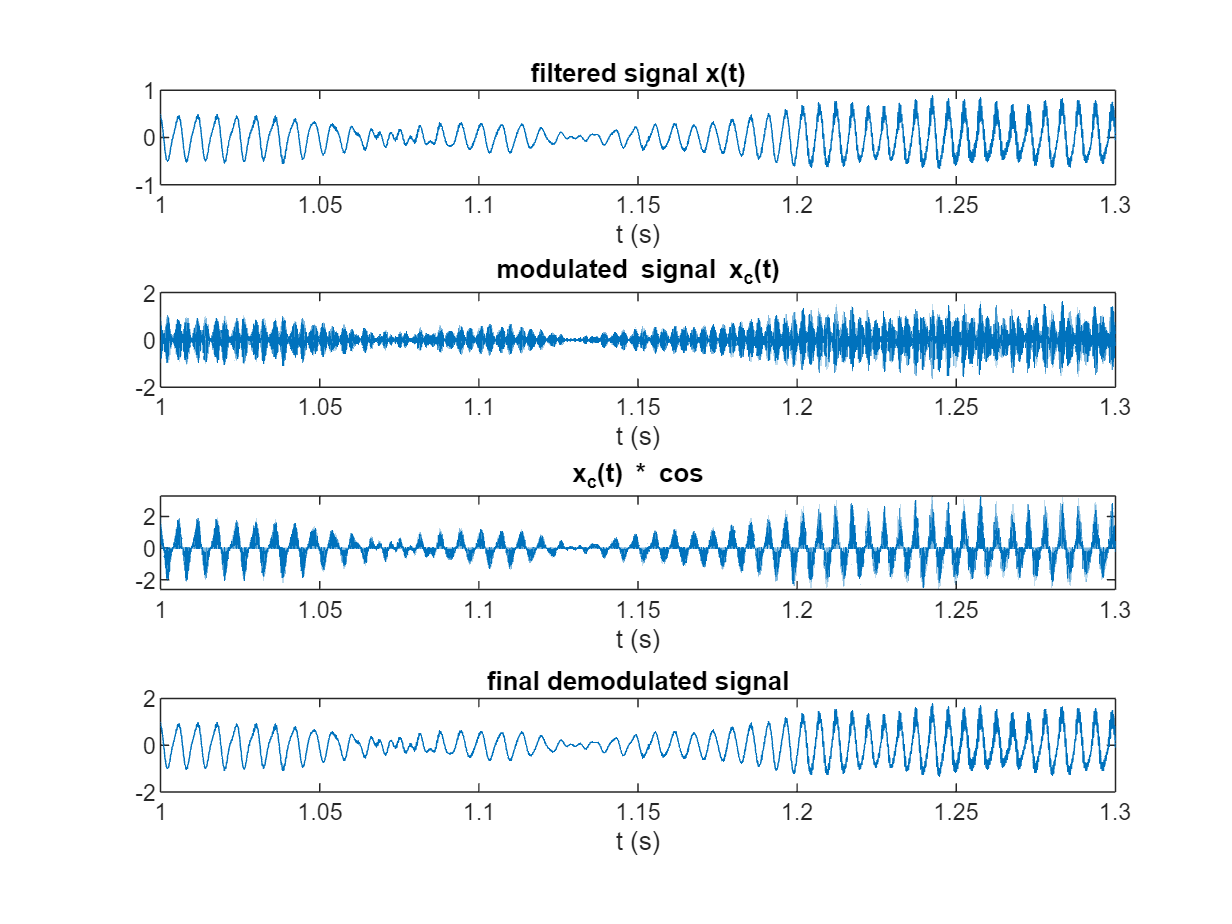

figure;
subplot(4,1,1);
plot (time_domain, t2_filtered_5k);
xlabel('t (s)');
title('filtered signal x(t)');
xlim([1,1.3]);
subplot(4,1,2);
plot(time_domain, x_c);
xlabel('t (s)');
title('modulated signal x_c(t)');
xlim([1,1.3]);
subplot(4,1,3);
plot(time_domain, x_dm);
xlabel('t (s)');
title('x_c(t) * cos');
xlim([1,1.3]);
subplot(4,1,4);
plot(time_domain, x_final);
xlabel('t (s)');
title('final demodulated signal');
xlim([1,1.3]);

## phase shift pi/4

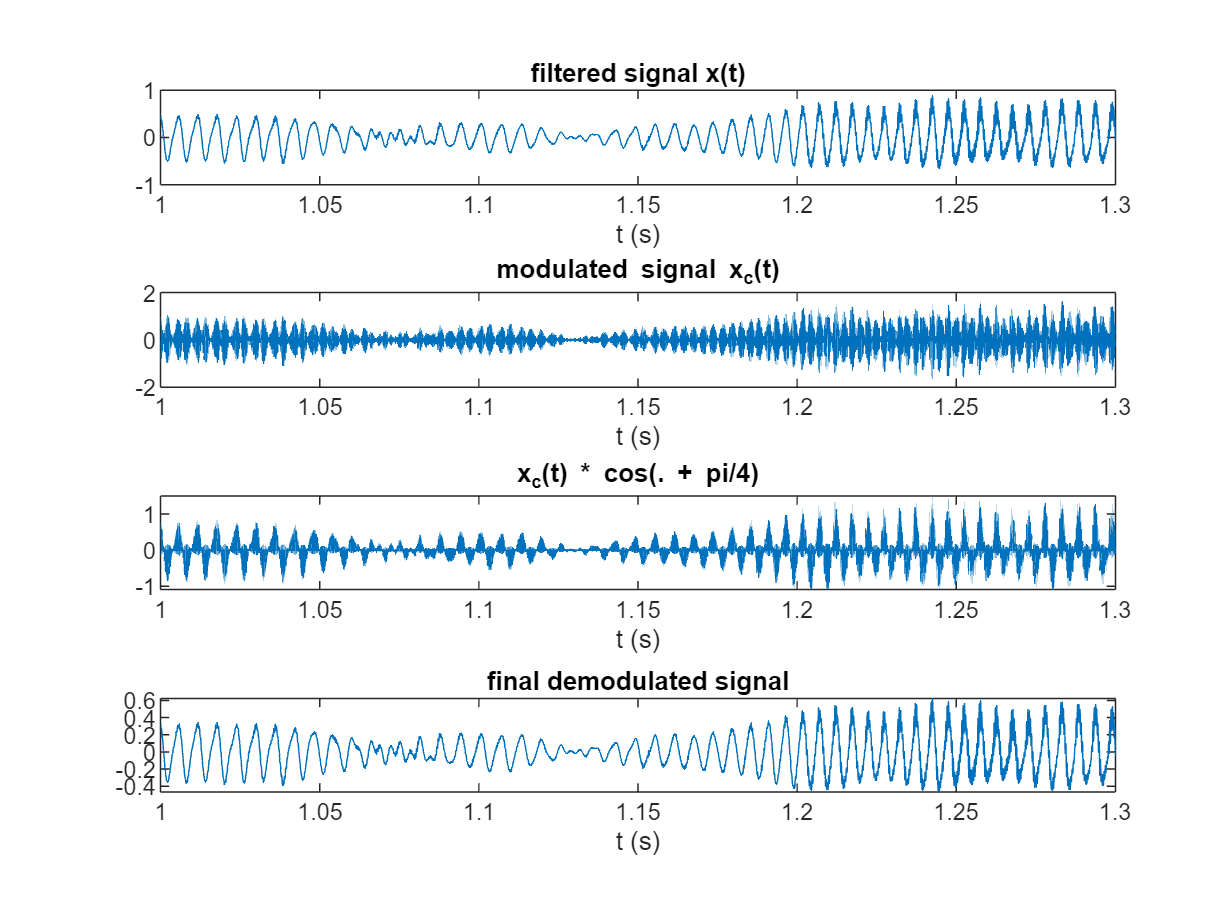


x_dm_pi4 = cos(2*pi*fc*time_domain2 + pi/4) .* x_c;
F_x_dm_pi4 = fftshift(fft(x_dm_pi4));
F_X_final_pi4 = LPfilter(F_x_dm_pi4, freq_domain, 5000);
x_final_pi4 = ifft(ifftshift(F_X_final_pi4));

% sound(x_final_pi4, FS);


%% plotting in time domain
figure;
subplot(4,1,1);
plot (time_domain, t2_filtered_5k);
xlabel('t (s)');
title('filtered signal x(t)');
xlim([1,1.3]);
subplot(4,1,2);
plot(time_domain, x_c);
xlabel('t (s)');
title('modulated signal x_c(t)');
xlim([1,1.3]);
subplot(4,1,3);
plot(time_domain, x_dm_pi4);
xlabel('t (s)');
title('x_c(t) * cos(. + pi/4)');
xlim([1,1.3]);
subplot(4,1,4);
plot(time_domain, x_final_pi4);
xlabel('t (s)');
title('final demodulated signal');
xlim([1,1.3]);

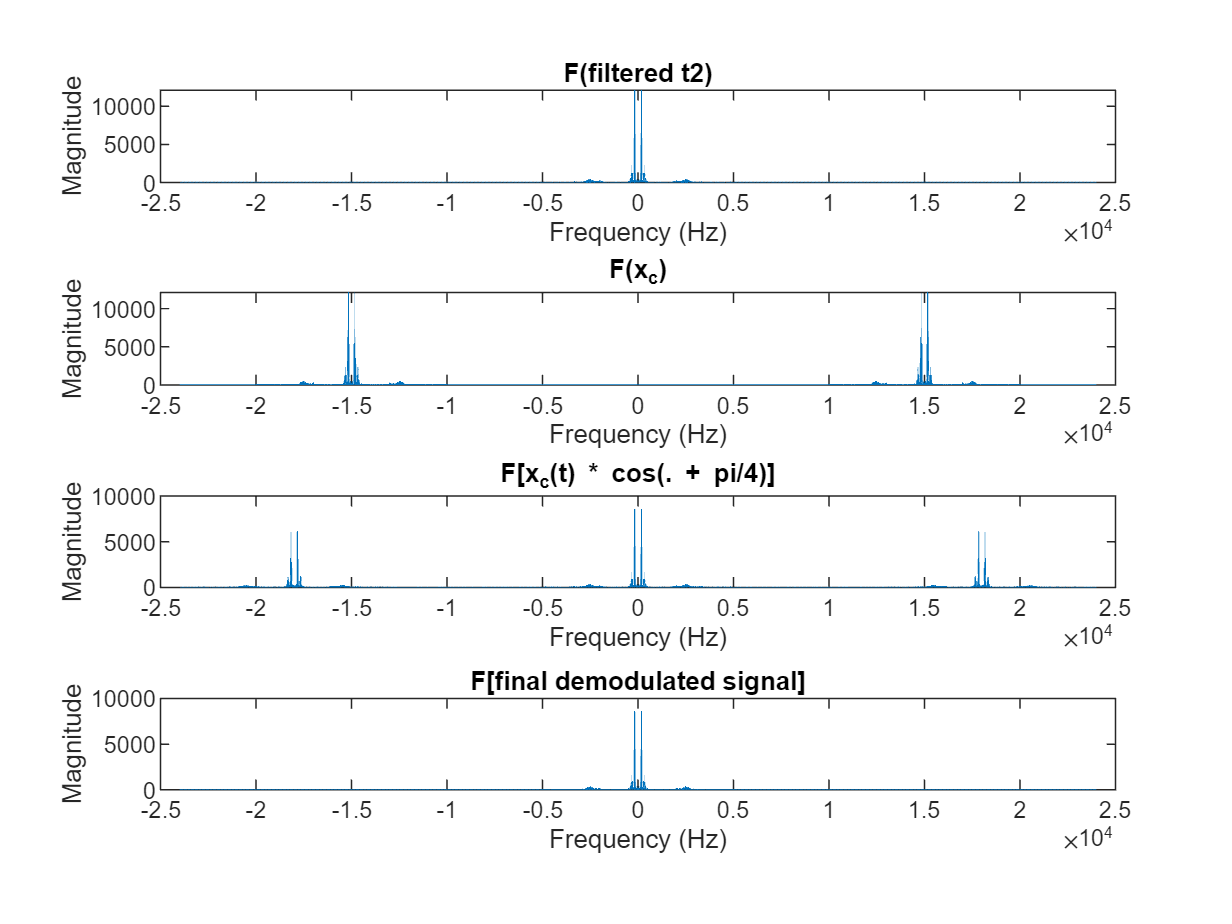

%% plotting in freq. domain
figure;
subplot(4,1,1);
plot(freq_domain,abs(Ft2_filtered_5k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(filtered t2)');
subplot(4,1,2);
plot(freq_domain,abs(F_x_c));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(x_c)');
subplot(4,1,3);
plot(freq_domain, abs(F_x_dm_pi4));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x_c(t) * cos(. + pi/4)]');
subplot(4,1,4);
plot(freq_domain, abs(F_X_final_pi4));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[final demodulated signal]');

## phase shift pi/2.25

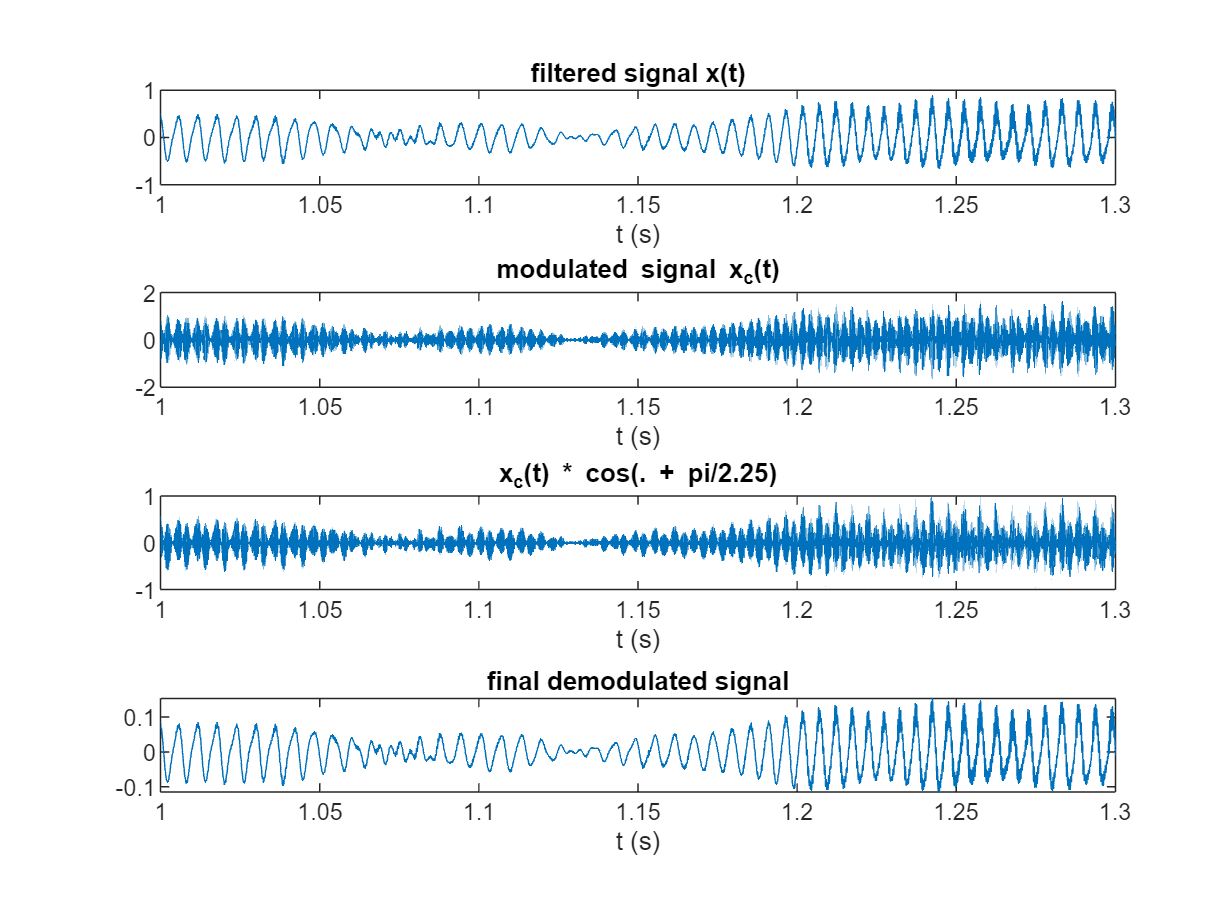


x_dm_pi225 = cos(2*pi*fc*time_domain2 + pi/2.25) .* x_c;
F_x_dm_pi225 = fftshift(fft(x_dm_pi225));
F_X_final_pi225 = LPfilter(F_x_dm_pi225, freq_domain, 5000);
x_final_pi225 = ifft(ifftshift(F_X_final_pi225));

% sound(x_final_pi225, FS);


%% plotting in time domain
figure;
subplot(4,1,1);
plot (time_domain, t2_filtered_5k);
xlabel('t (s)');
title('filtered signal x(t)');
xlim([1,1.3]);
subplot(4,1,2);
plot(time_domain, x_c);
xlabel('t (s)');
title('modulated signal x_c(t)');
xlim([1,1.3]);
subplot(4,1,3);
plot(time_domain, x_dm_pi225);
xlabel('t (s)');
title('x_c(t) * cos(. + pi/2.25)');
xlim([1,1.3]);
subplot(4,1,4);
plot(time_domain, x_final_pi225);
xlabel('t (s)');
title('final demodulated signal');
xlim([1,1.3]);

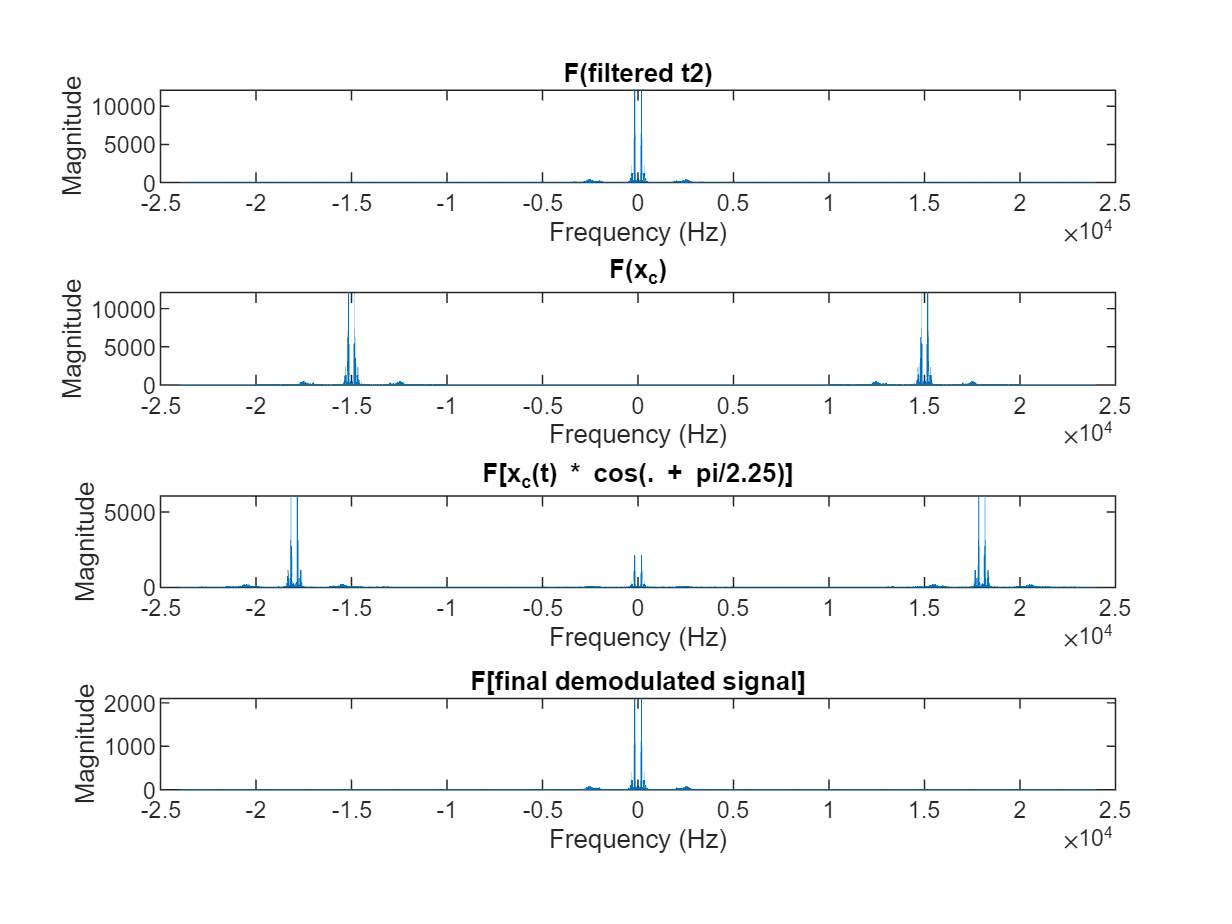

%% plotting in freq. domain
figure;
subplot(4,1,1);
plot(freq_domain,abs(Ft2_filtered_5k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(filtered t2)');
subplot(4,1,2);
plot(freq_domain,abs(F_x_c));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(x_c)');
subplot(4,1,3);
plot(freq_domain, abs(F_x_dm_pi225));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x_c(t) * cos(. + pi/2.25)]');
subplot(4,1,4);
plot(freq_domain, abs(F_X_final_pi225));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[final demodulated signal]');

## phase shift pi/2.04

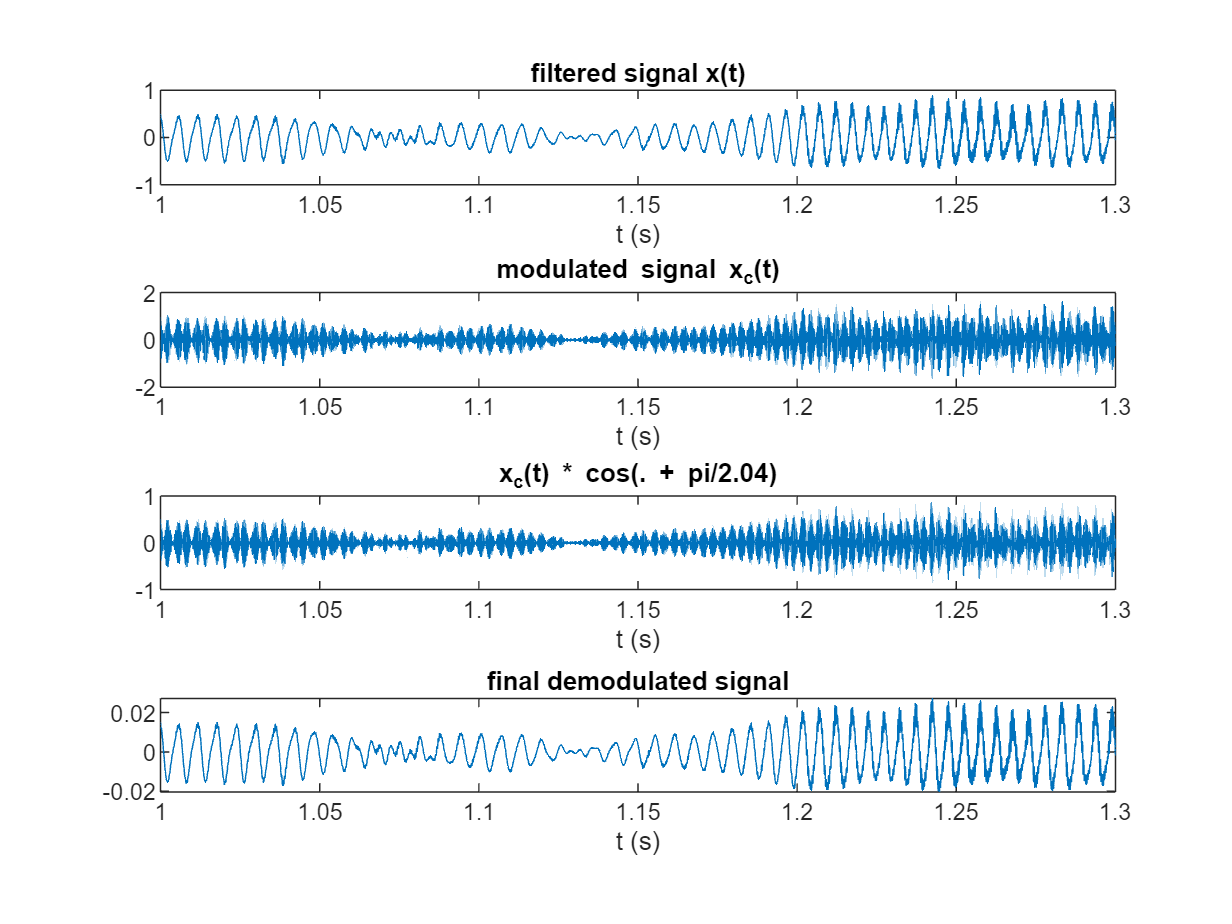


x_dm_pi204 = cos(2*pi*fc*time_domain2 + pi/2.04) .* x_c;
F_x_dm_pi204 = fftshift(fft(x_dm_pi204));

F_X_final_pi204 = LPfilter(F_x_dm_pi204, freq_domain, 5000);
x_final_pi204 = ifft(ifftshift(F_X_final_pi204));

% sound(x_final_pi204, FS);


%% plotting in time domain
figure;
subplot(4,1,1);
plot (time_domain, t2_filtered_5k);
xlabel('t (s)');
title('filtered signal x(t)');
xlim([1,1.3]);
subplot(4,1,2);
plot(time_domain, x_c);
xlabel('t (s)');
title('modulated signal x_c(t)');
xlim([1,1.3]);
subplot(4,1,3);
plot(time_domain, x_dm_pi204);
xlabel('t (s)');
title('x_c(t) * cos(. + pi/2.04)');
xlim([1,1.3]);
subplot(4,1,4);
plot(time_domain, x_final_pi204);
xlabel('t (s)');
title('final demodulated signal');
xlim([1,1.3]);

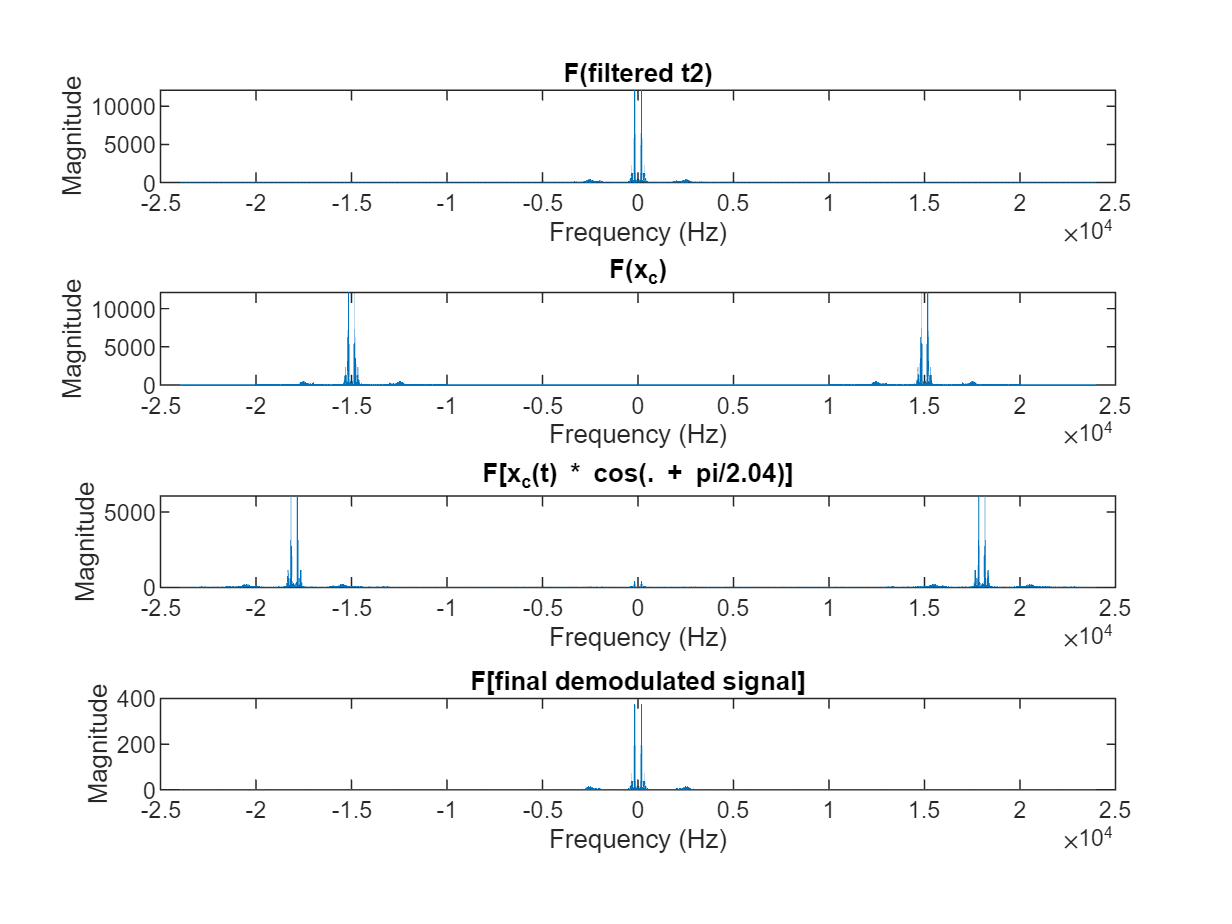

%% plotting in freq. domain
figure;
subplot(4,1,1);
plot(freq_domain,abs(Ft2_filtered_5k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(filtered t2)');
subplot(4,1,2);
plot(freq_domain,abs(F_x_c));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(x_c)');
subplot(4,1,3);
plot(freq_domain, abs(F_x_dm_pi204));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x_c(t) * cos(. + pi/2.04)]');
subplot(4,1,4);
plot(freq_domain, abs(F_X_final_pi204));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[final demodulated signal]');

## phase shift pi/2

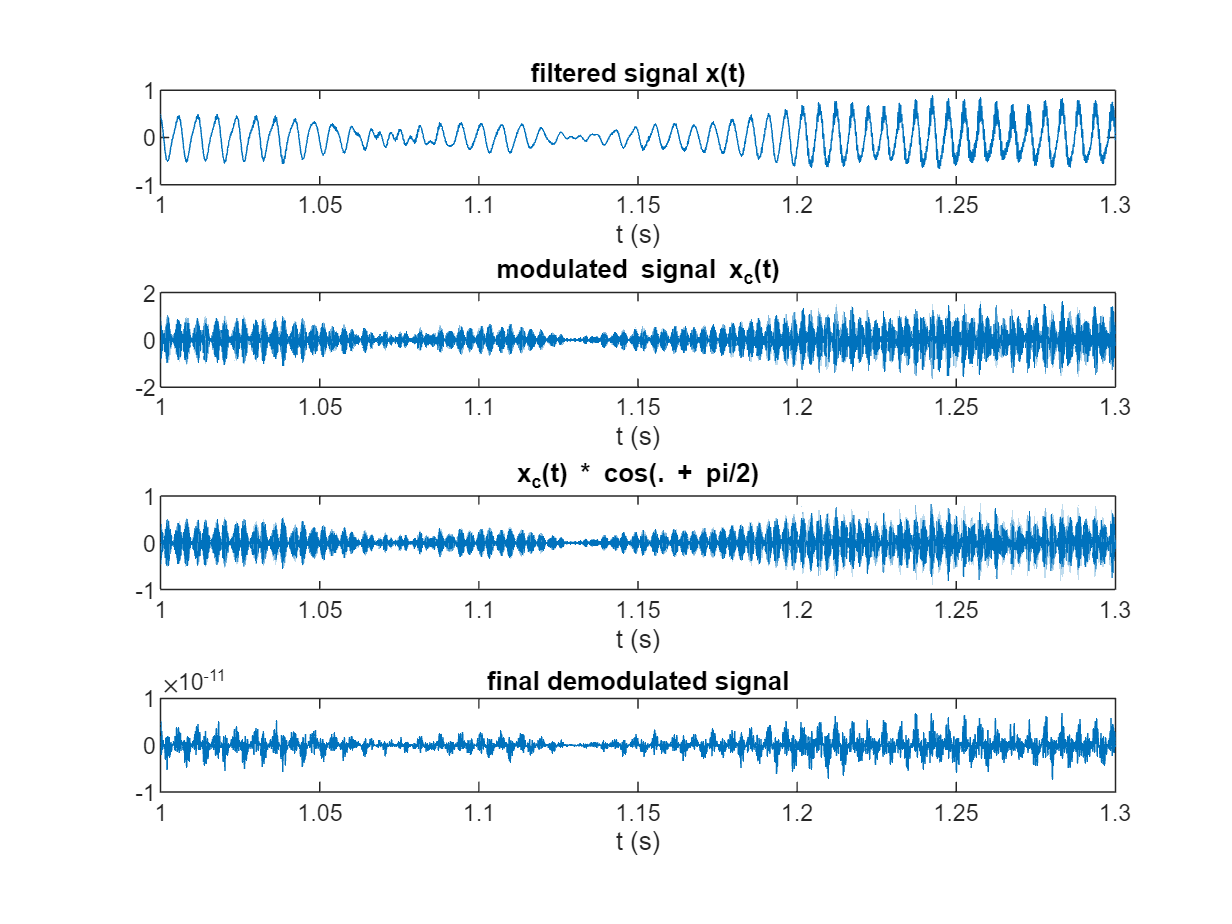


x_dm_pi2 = cos(2*pi*fc*time_domain2 + pi/2.0) .* x_c;
F_x_dm_pi2 = fftshift(fft(x_dm_pi2));

F_X_final_pi2 = LPfilter(F_x_dm_pi2, freq_domain, 5000);
x_final_pi2 = ifft(ifftshift(F_X_final_pi2));

% sound(x_final_pi2, FS);


%% plotting in time domain
figure;
subplot(4,1,1);
plot (time_domain, t2_filtered_5k);
xlabel('t (s)');
title('filtered signal x(t)');
xlim([1,1.3]);
subplot(4,1,2);
plot(time_domain, x_c);
xlabel('t (s)');
title('modulated signal x_c(t)');
xlim([1,1.3]);
subplot(4,1,3);
plot(time_domain, x_dm_pi2);
xlabel('t (s)');
title('x_c(t) * cos(. + pi/2)');
xlim([1,1.3]);
subplot(4,1,4);
plot(time_domain, x_final_pi2);
xlabel('t (s)');
title('final demodulated signal');
xlim([1,1.3]);

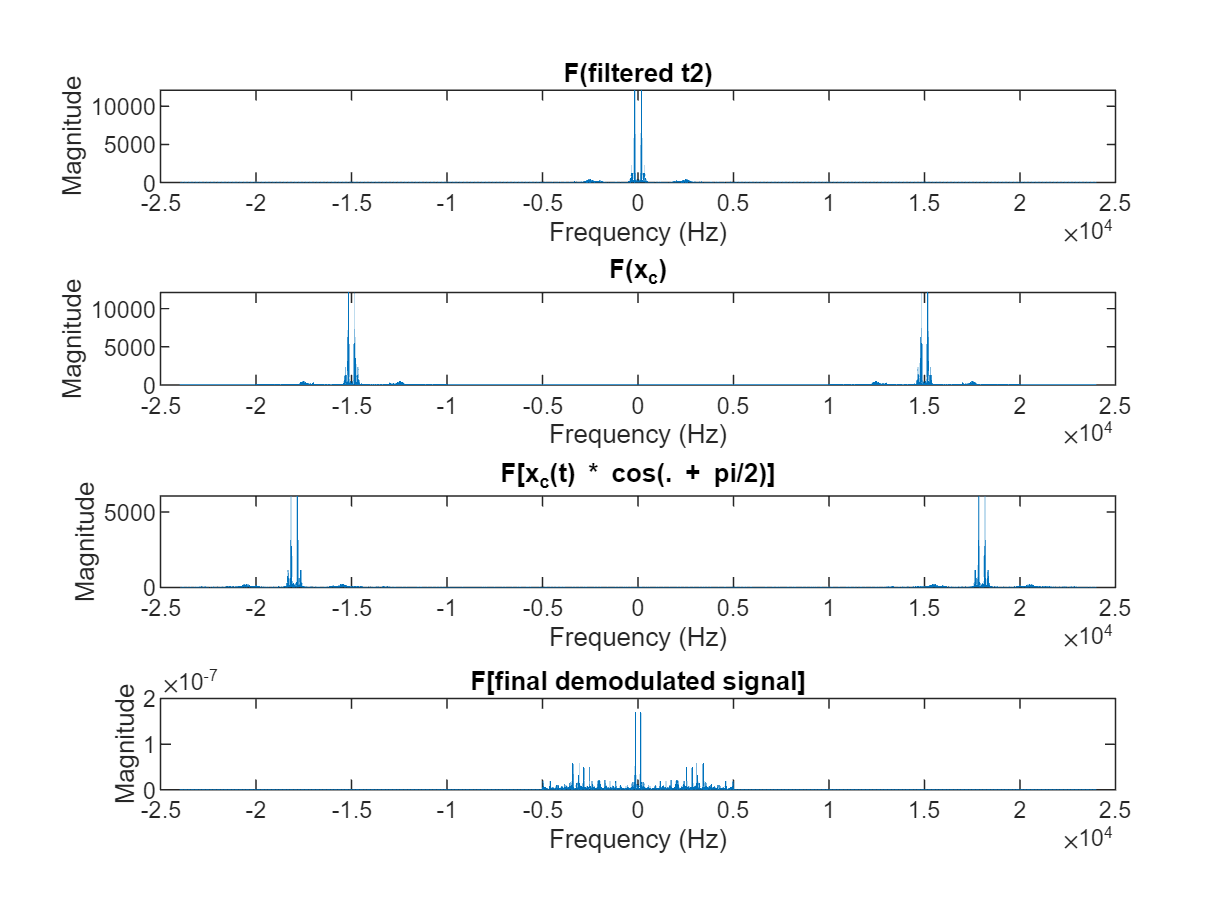

%% plotting in freq. domain
figure;
subplot(4,1,1);
plot(freq_domain,abs(Ft2_filtered_5k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(filtered t2)');
subplot(4,1,2);
plot(freq_domain,abs(F_x_c));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(x_c)');
subplot(4,1,3);
plot(freq_domain, abs(F_x_dm_pi2));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x_c(t) * cos(. + pi/2)]');
subplot(4,1,4);
plot(freq_domain, abs(F_X_final_pi2));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[final demodulated signal]');

% sound(t2, FS);
% sound(t2_filtered_5k, FS);
% sound(x_final, FS);
% sound(x_final_pi4, FS);
% sound(x_final_pi225, FS);
% sound(x_final_pi204, FS);
% sound(x_final_pi2, FS);

## frequency shift 0.01%

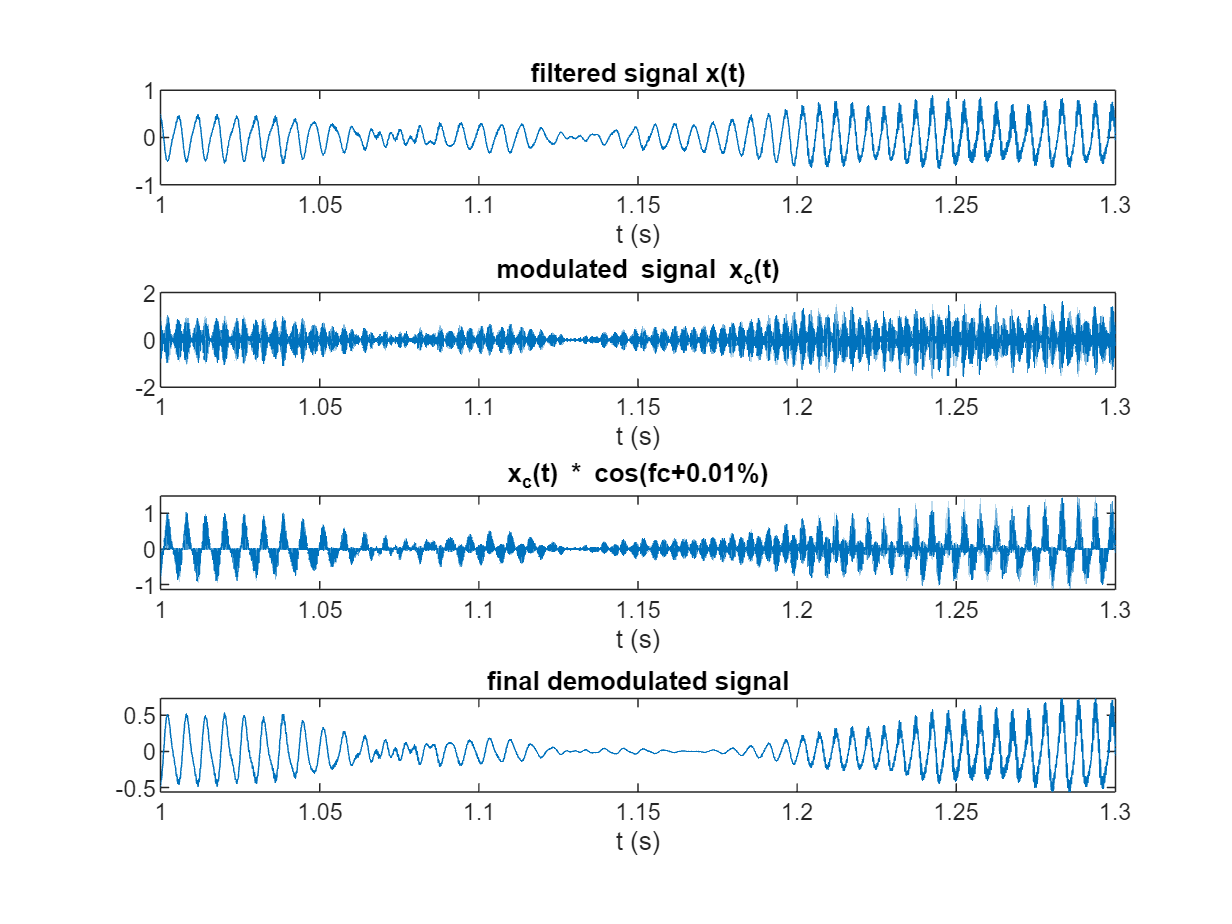


x_dm_f1_100 = cos(2*pi*( fc*( 1+(0.01/100.0)) )*time_domain2) .* x_c;
F_x_dm_f1_100 = fftshift(fft(x_dm_f1_100));

F_X_final_f1_100 = LPfilter(F_x_dm_f1_100, freq_domain, 5000);
x_final_f1_100 = ifft(ifftshift(F_X_final_f1_100));

% sound(x_final_f1_100, FS);


%% plotting in time domain
figure;
subplot(4,1,1);
plot (time_domain, t2_filtered_5k);
xlabel('t (s)');
title('filtered signal x(t)');
xlim([1,1.3]);
subplot(4,1,2);
plot(time_domain, x_c);
xlabel('t (s)');
title('modulated signal x_c(t)');
xlim([1,1.3]);
subplot(4,1,3);
plot(time_domain, x_dm_f1_100);
xlabel('t (s)');
title('x_c(t) * cos(fc+0.01%)');
xlim([1,1.3]);
subplot(4,1,4);
plot(time_domain, x_final_f1_100);
xlabel('t (s)');
title('final demodulated signal');
xlim([1,1.3]);

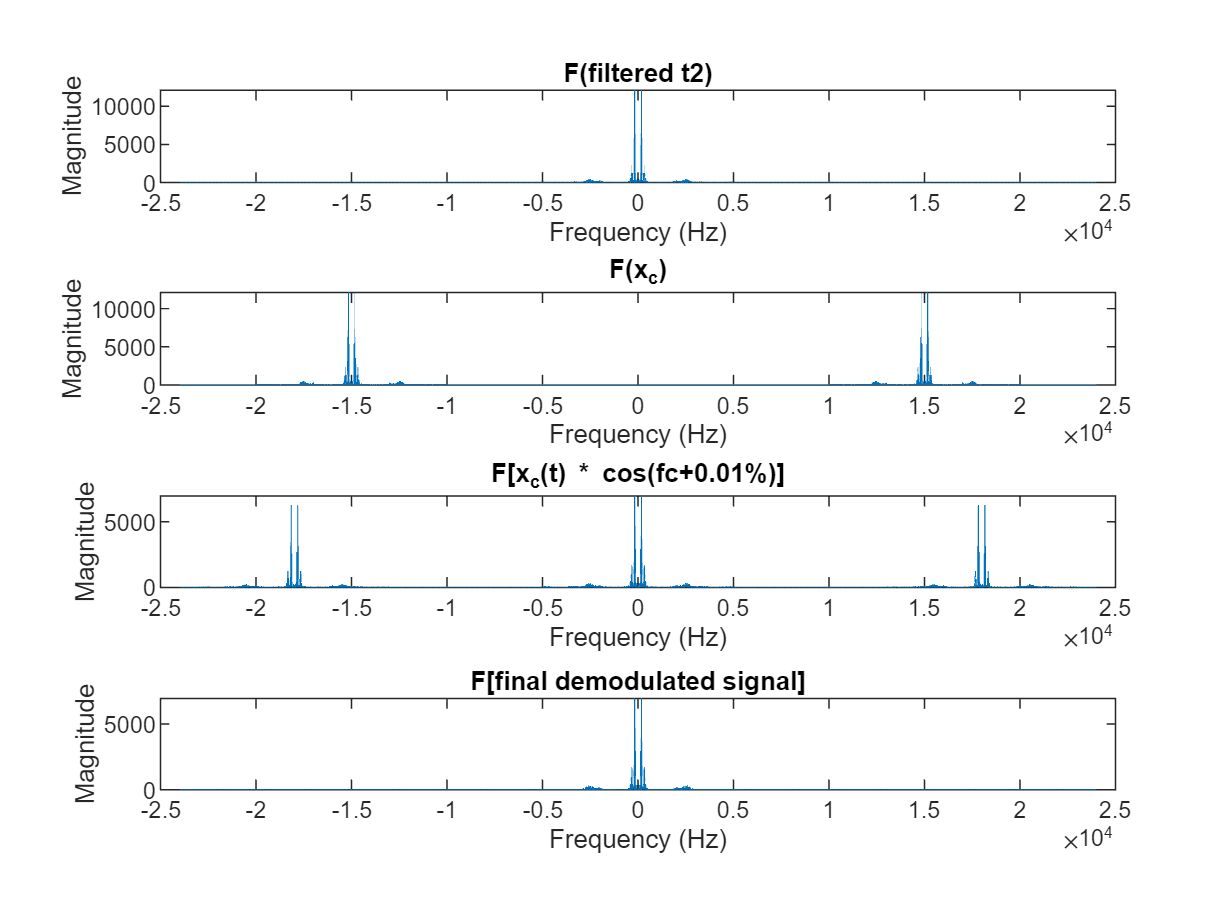

%% plotting in freq. domain
figure;
subplot(4,1,1);
plot(freq_domain,abs(Ft2_filtered_5k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(filtered t2)');
subplot(4,1,2);
plot(freq_domain,abs(F_x_c));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(x_c)');
subplot(4,1,3);
plot(freq_domain, abs(F_x_dm_f1_100));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x_c(t) * cos(fc+0.01%)]');
subplot(4,1,4);
plot(freq_domain, abs(F_X_final_f1_100));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[final demodulated signal]');

## frequency shift 0.1%

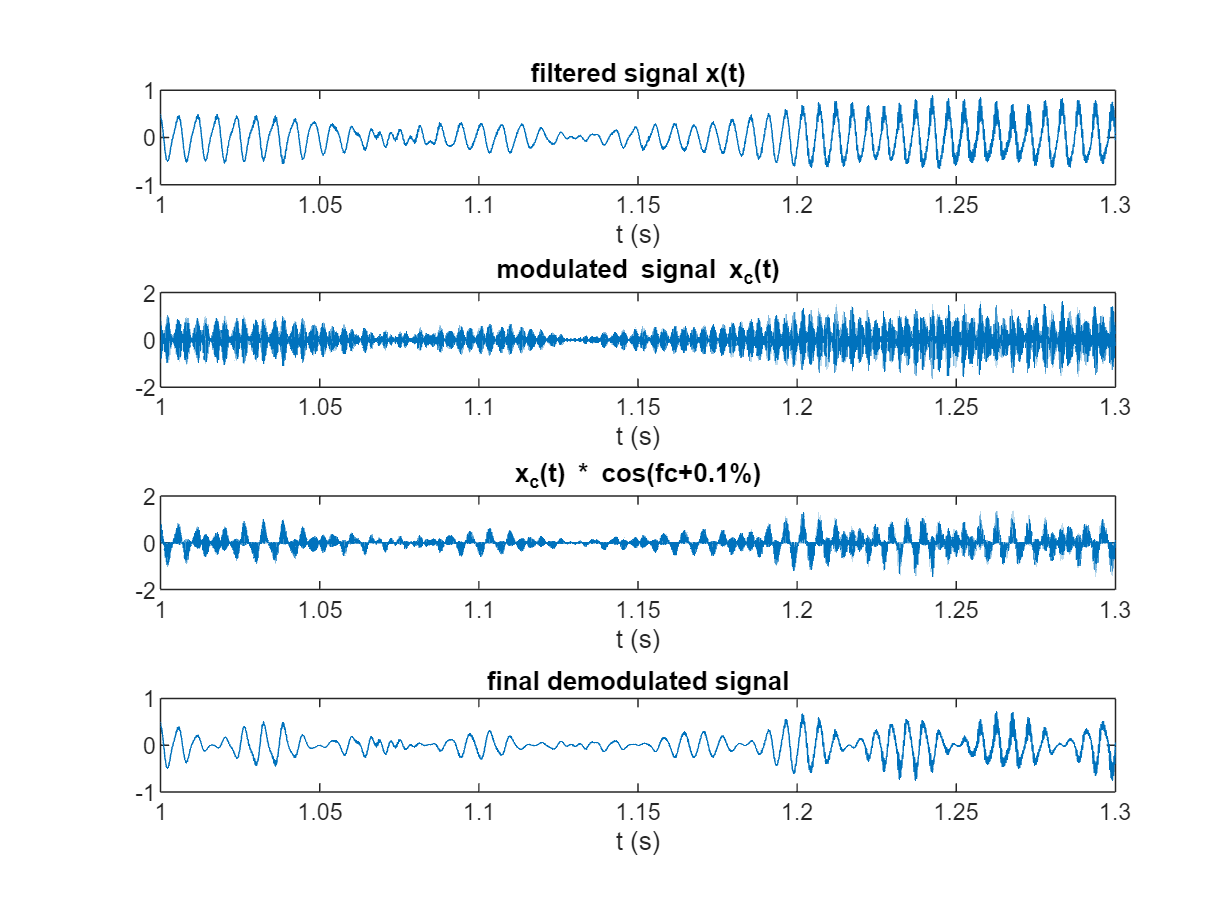


x_dm_f1_10 = cos(2*pi*( fc*( 1+(0.1/100.0)) )*time_domain2) .* x_c;
F_x_dm_f1_10 = fftshift(fft(x_dm_f1_10));

F_X_final_f1_10 = LPfilter(F_x_dm_f1_10, freq_domain, 5000);
x_final_f1_10 = ifft(ifftshift(F_X_final_f1_10));

% sound(x_final_f1_10, FS);


%% plotting in time domain
figure;
subplot(4,1,1);
plot (time_domain, t2_filtered_5k);
xlabel('t (s)');
title('filtered signal x(t)');
xlim([1,1.3]);
subplot(4,1,2);
plot(time_domain, x_c);
xlabel('t (s)');
title('modulated signal x_c(t)');
xlim([1,1.3]);
subplot(4,1,3);
plot(time_domain, x_dm_f1_10);
xlabel('t (s)');
title('x_c(t) * cos(fc+0.1%)');
xlim([1,1.3]);
subplot(4,1,4);
plot(time_domain, x_final_f1_10);
xlabel('t (s)');
title('final demodulated signal');
xlim([1,1.3]);

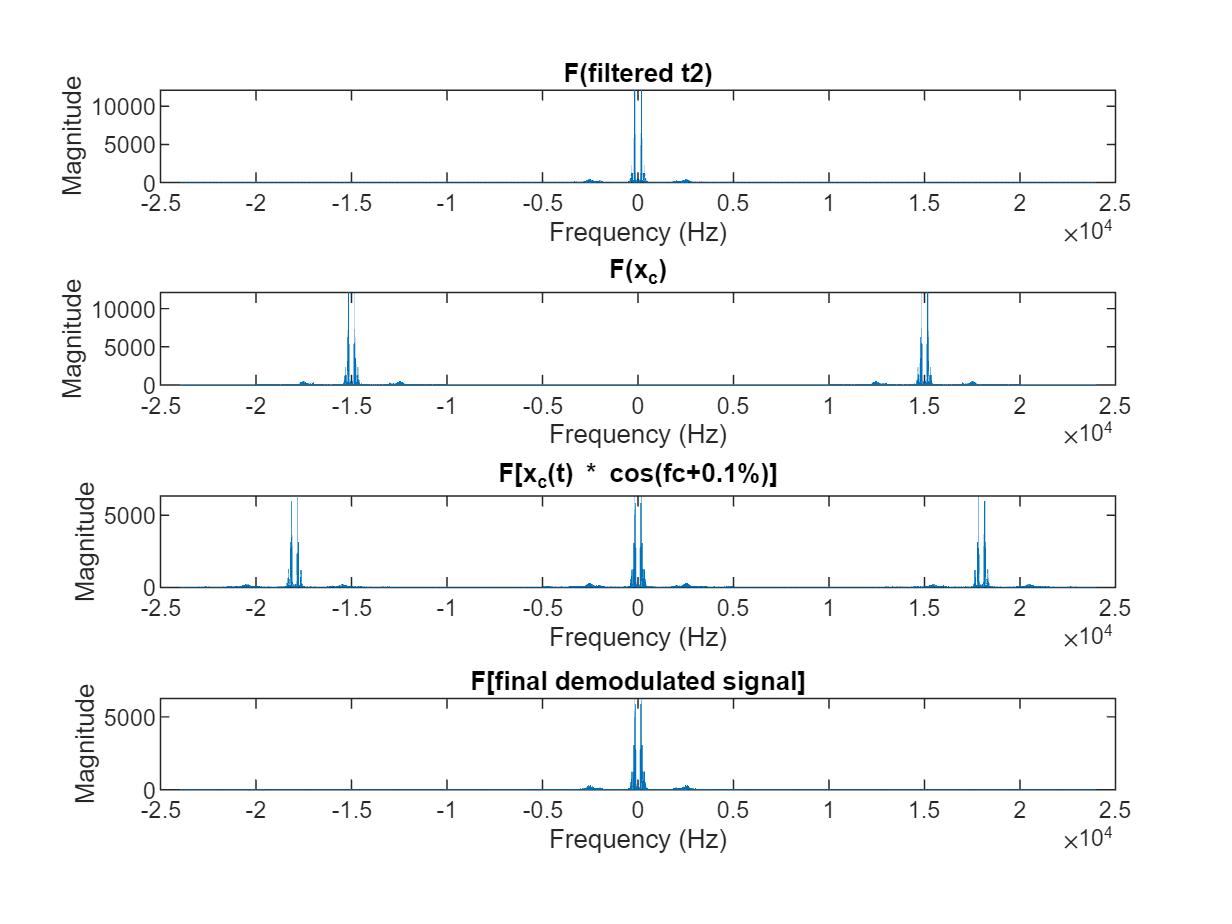


%% plotting in freq. domain
figure;
subplot(4,1,1);
plot(freq_domain,abs(Ft2_filtered_5k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(filtered t2)');
subplot(4,1,2);
plot(freq_domain,abs(F_x_c));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(x_c)');
subplot(4,1,3);
plot(freq_domain, abs(F_x_dm_f1_10));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x_c(t) * cos(fc+0.1%)]');
subplot(4,1,4);
plot(freq_domain, abs(F_X_final_f1_10));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[final demodulated signal]');

## frequency shift 1%

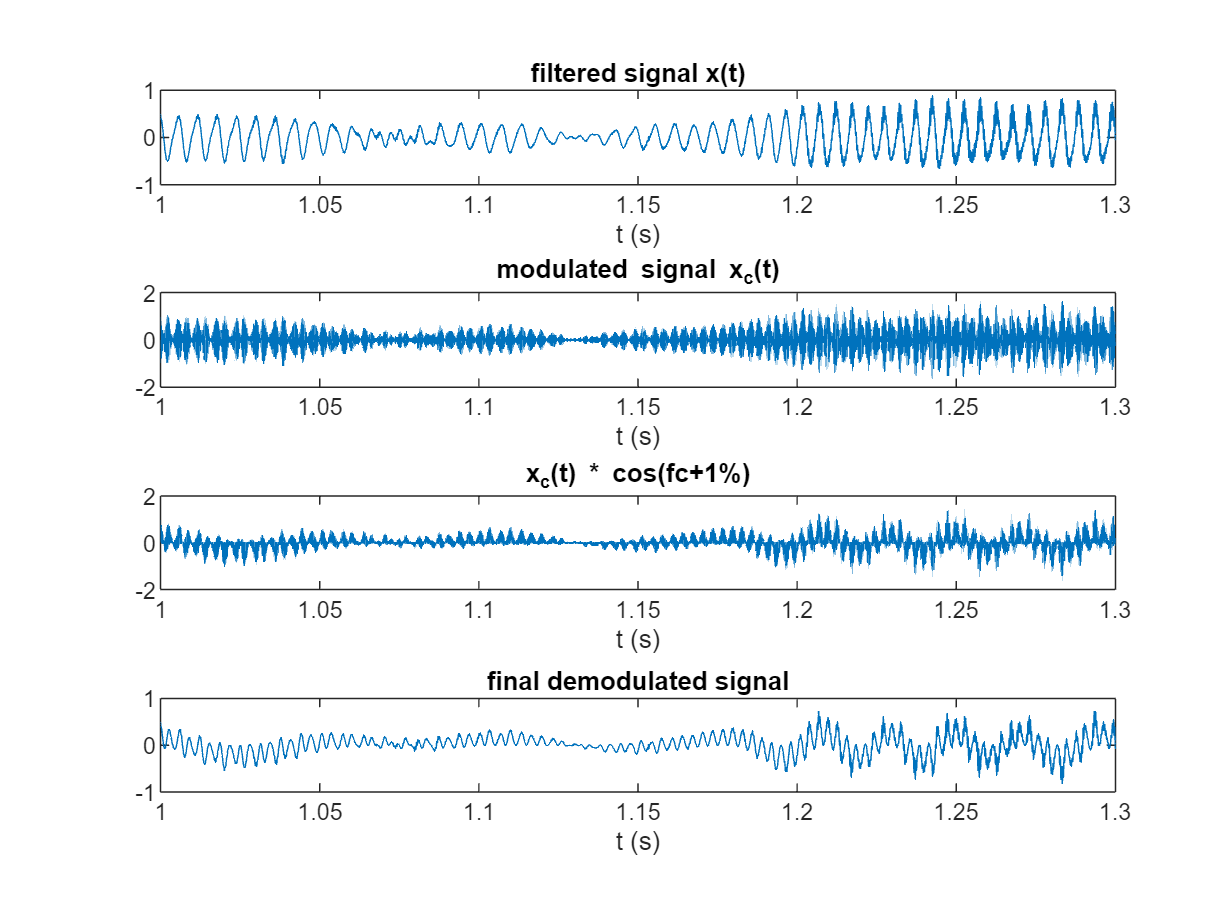


x_dm_f1 = cos(2*pi*( fc*( 1+(1/100.0)) )*time_domain2) .* x_c;
F_x_dm_f1 = fftshift(fft(x_dm_f1));

F_X_final_f1 = LPfilter(F_x_dm_f1, freq_domain, 5000);
x_final_f1 = ifft(ifftshift(F_X_final_f1));

% sound(x_final_f1, FS);


%% plotting in time domain
figure;
subplot(4,1,1);
plot (time_domain, t2_filtered_5k);
xlabel('t (s)');
title('filtered signal x(t)');
xlim([1,1.3]);
subplot(4,1,2);
plot(time_domain, x_c);
xlabel('t (s)');
title('modulated signal x_c(t)');
xlim([1,1.3]);
subplot(4,1,3);
plot(time_domain, x_dm_f1);
xlabel('t (s)');
title('x_c(t) * cos(fc+1%)');
xlim([1,1.3]);
subplot(4,1,4);
plot(time_domain, x_final_f1);
xlabel('t (s)');
title('final demodulated signal');
xlim([1,1.3]);

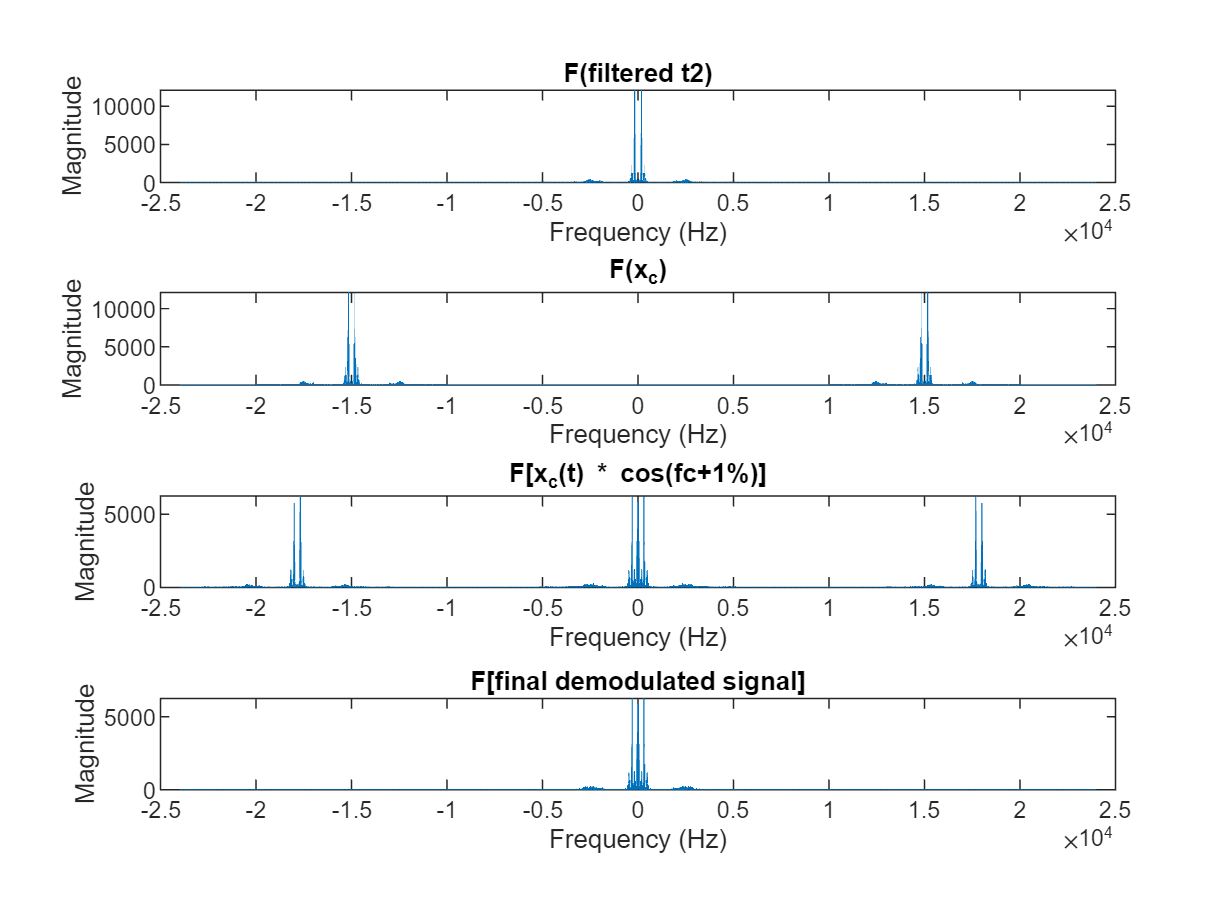


%% plotting in freq. domain
figure;
subplot(4,1,1);
plot(freq_domain,abs(Ft2_filtered_5k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(filtered t2)');
subplot(4,1,2);
plot(freq_domain,abs(F_x_c));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(x_c)');
subplot(4,1,3);
plot(freq_domain, abs(F_x_dm_f1));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x_c(t) * cos(fc+1%)]');
subplot(4,1,4);
plot(freq_domain, abs(F_X_final_f1));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[final demodulated signal]');

## frequency shift 5%

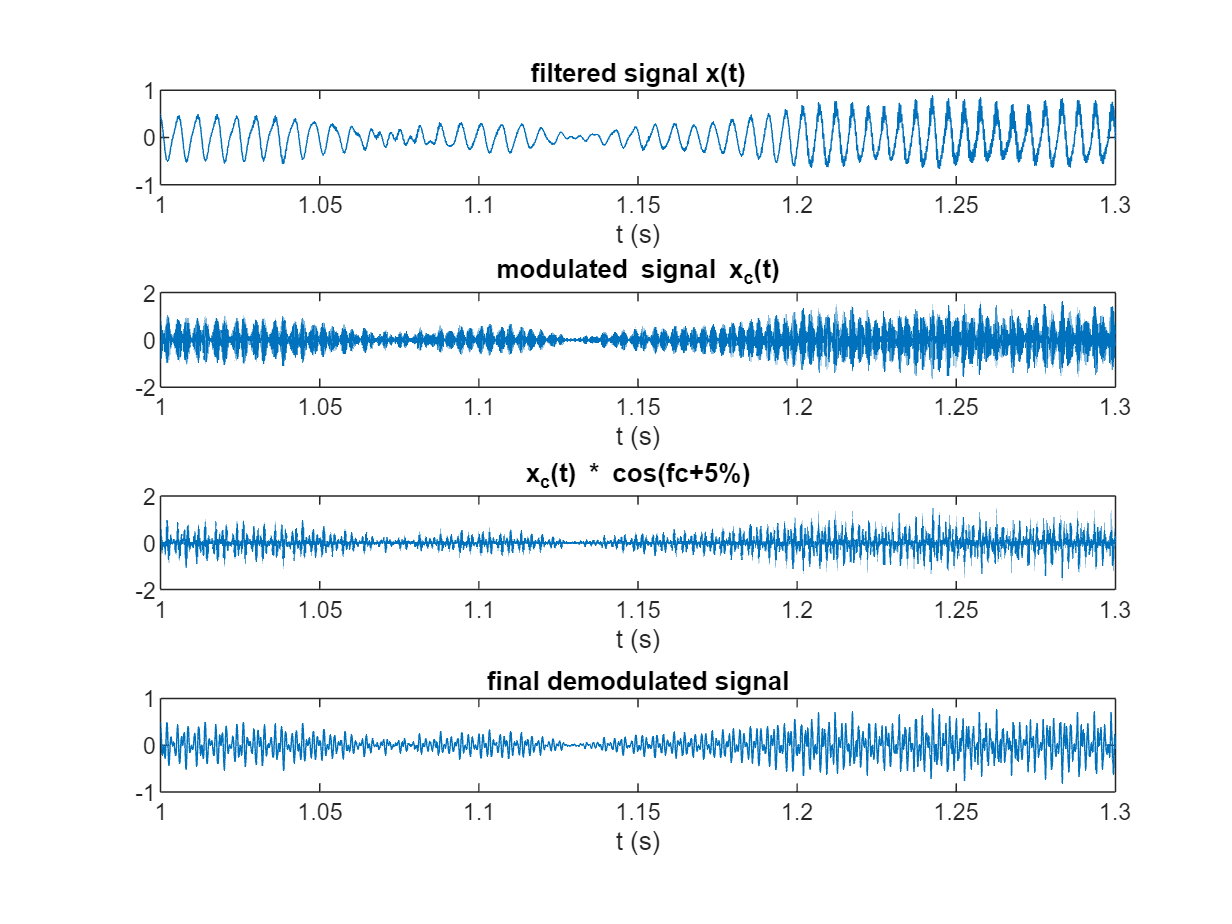


x_dm_f5 = cos(2*pi*( fc*( 1+(5/100.0)) )*time_domain2) .* x_c;
F_x_dm_f5 = fftshift(fft(x_dm_f5));

F_X_final_f5 = LPfilter(F_x_dm_f5, freq_domain, 5000);
x_final_f5 = ifft(ifftshift(F_X_final_f5));

% sound(x_final_f5, FS);


%% plotting in time domain
figure;
subplot(4,1,1);
plot (time_domain, t2_filtered_5k);
xlabel('t (s)');
title('filtered signal x(t)');
xlim([1,1.3]);
subplot(4,1,2);
plot(time_domain, x_c);
xlabel('t (s)');
title('modulated signal x_c(t)');
xlim([1,1.3]);
subplot(4,1,3);
plot(time_domain, x_dm_f5);
xlabel('t (s)');
title('x_c(t) * cos(fc+5%)');
xlim([1,1.3]);
subplot(4,1,4);
plot(time_domain, x_final_f5);
xlabel('t (s)');
title('final demodulated signal');
xlim([1,1.3]);

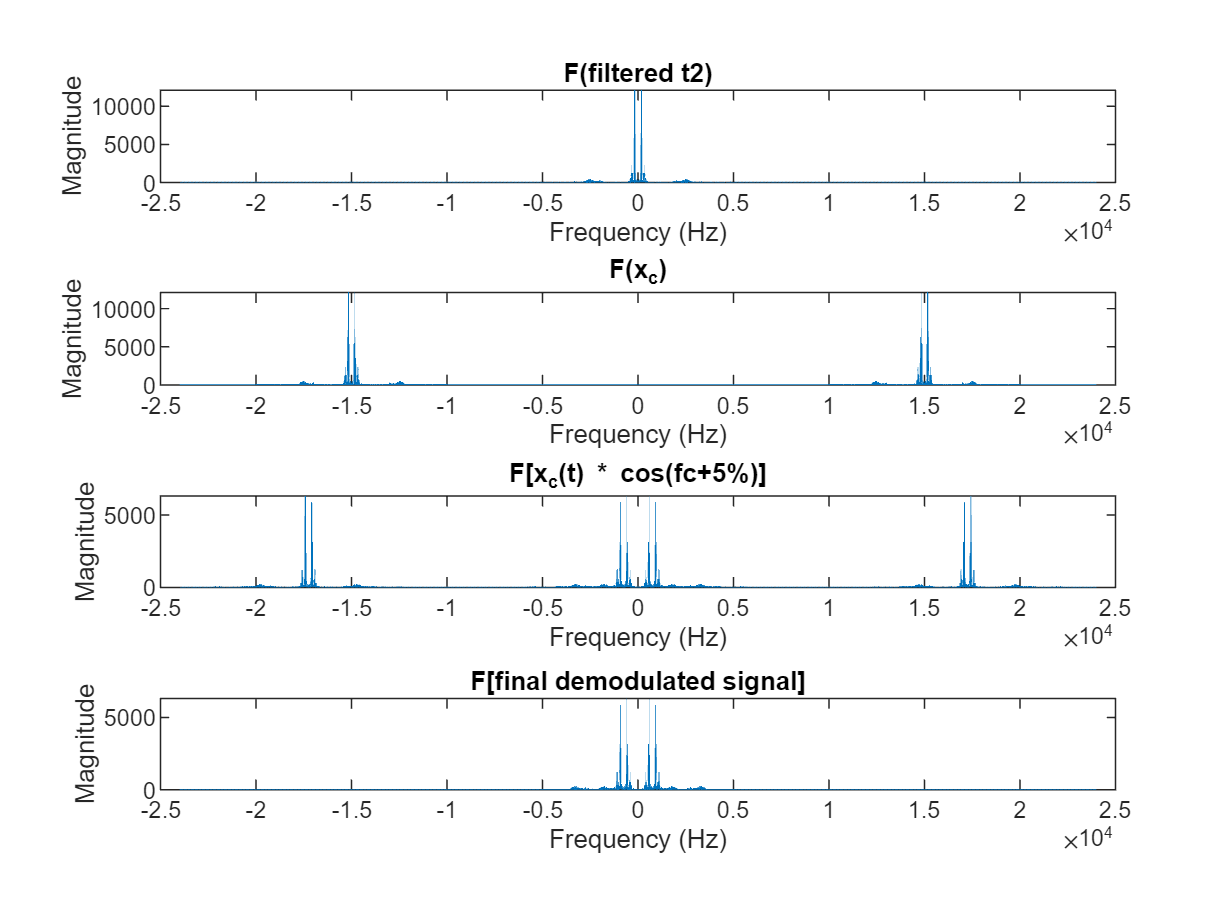


%% plotting in freq. domain
figure;
subplot(4,1,1);
plot(freq_domain,abs(Ft2_filtered_5k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(filtered t2)');
subplot(4,1,2);
plot(freq_domain,abs(F_x_c));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(x_c)');
subplot(4,1,3);
plot(freq_domain, abs(F_x_dm_f5));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x_c(t) * cos(fc+5%)]');
subplot(4,1,4);
plot(freq_domain, abs(F_X_final_f5));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[final demodulated signal]');

## frequency shift 10%

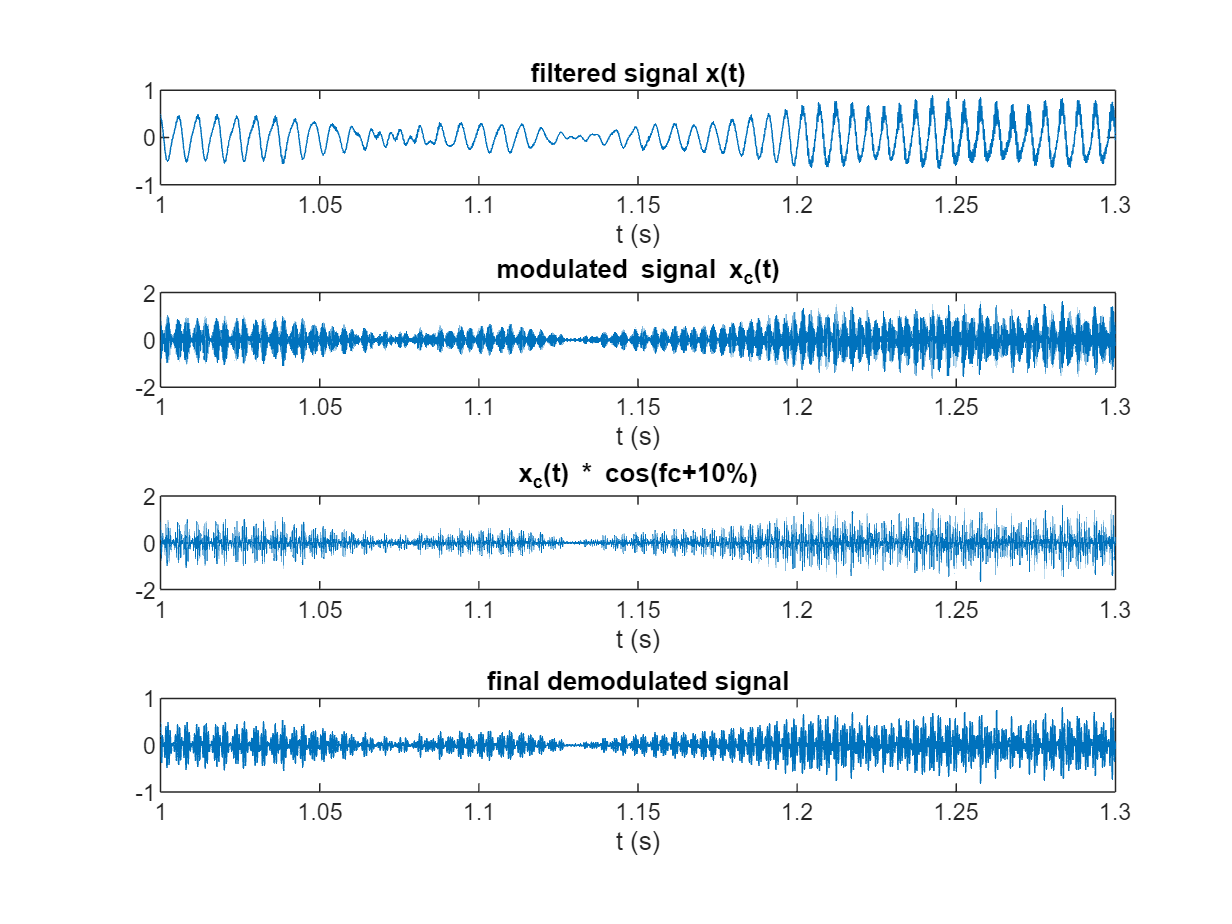


x_dm_f10 = cos(2*pi*( fc*( 1+(10/100.0)) )*time_domain2) .* x_c;
F_x_dm_f10 = fftshift(fft(x_dm_f10));

F_X_final_f10 = LPfilter(F_x_dm_f10, freq_domain, 5000);
x_final_f10 = ifft(ifftshift(F_X_final_f10));

% sound(x_final_f10, FS);


%% plotting in time domain
figure;
subplot(4,1,1);
plot (time_domain, t2_filtered_5k);
xlabel('t (s)');
title('filtered signal x(t)');
xlim([1,1.3]);
subplot(4,1,2);
plot(time_domain, x_c);
xlabel('t (s)');
title('modulated signal x_c(t)');
xlim([1,1.3]);
subplot(4,1,3);
plot(time_domain, x_dm_f10);
xlabel('t (s)');
title('x_c(t) * cos(fc+10%)');
xlim([1,1.3]);
subplot(4,1,4);
plot(time_domain, x_final_f10);
xlabel('t (s)');
title('final demodulated signal');
xlim([1,1.3]);

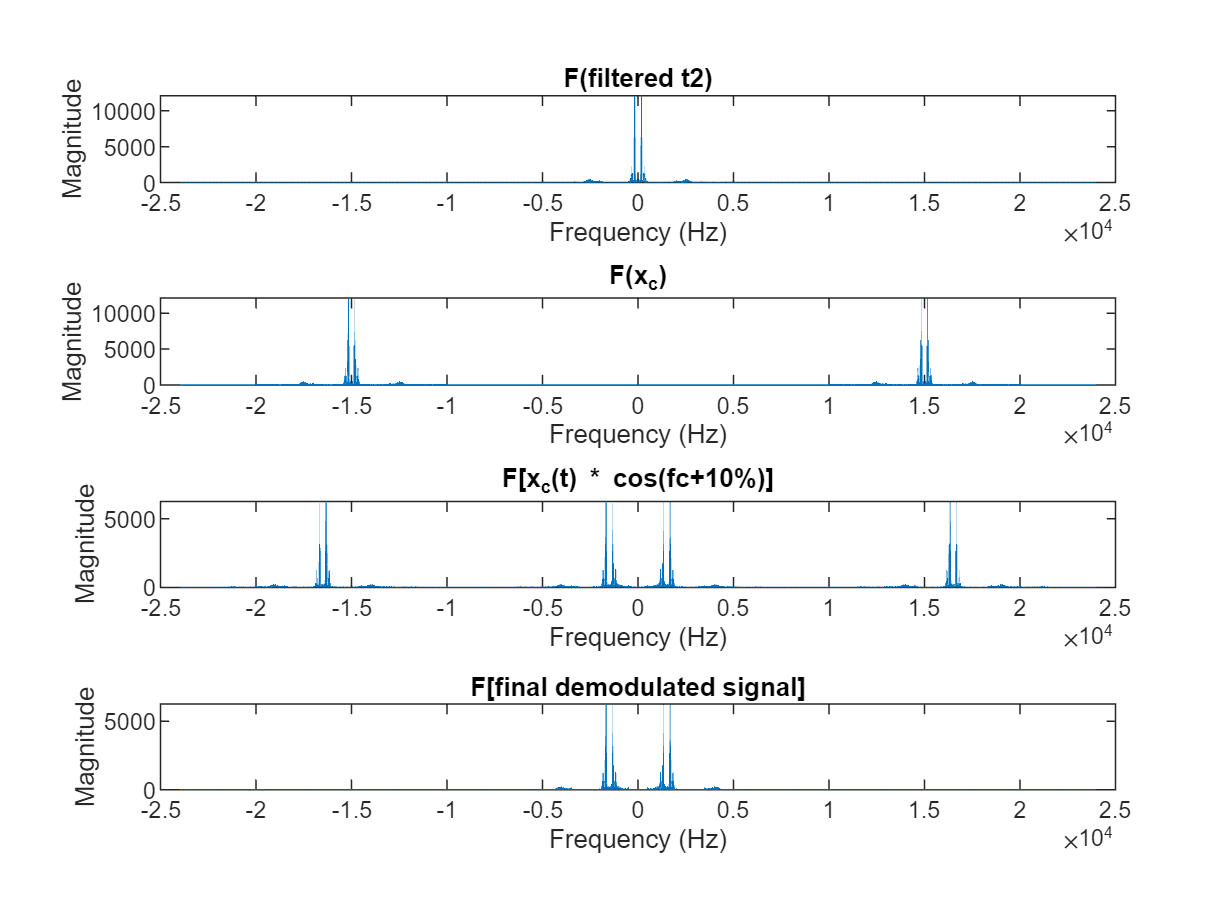


%% plotting in freq. domain
figure;
subplot(4,1,1);
plot(freq_domain,abs(Ft2_filtered_5k));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(filtered t2)');
subplot(4,1,2);
plot(freq_domain,abs(F_x_c));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F(x_c)');
subplot(4,1,3);
plot(freq_domain, abs(F_x_dm_f10));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[x_c(t) * cos(fc+10%)]');
subplot(4,1,4);
plot(freq_domain, abs(F_X_final_f10));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('F[final demodulated signal]');

% sound(t2, FS);
% sound(t2_filtered_5k, FS);
% sound(x_final, FS);
% sound(x_final_f1_100, FS);
% sound(x_final_f1_10, FS);
% sound(x_final_f1, FS);
% sound(x_final_f5, FS);
% sound(x_final_f10, FS);

function New_F = LPfilter(pre_F,freq_vector, f)
    n = length(freq_vector);
    New_F=zeros(n,1);
    for i = (1:n)
        if(abs(freq_vector(i)) < f)
            New_F(i)=pre_F(i); 
        end
    end
end